% add path to functions/scripts
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\KC_thresh_functions

% MANUALLY navigate to widefield/date_animalID folder

## LOADING MAPS VARS & BALL DATA

% load maps file for recording session (maps file generated by dfofMovie)
[df,frameT] = loadStage2MapsVars();

sizeDf =          171         211       55465


sizeFrameT =            1       55465


% load stimulus session data (comes from ballData folder on stimulus presentation computer)
[subjData,sessionFile,allStop,allResp,stimDetails,trialCond] = loadStage2subjSessVars();

% create figure title info
[date,subjName] = createTitleInfo(sessionFile,subjData);

date = 12 17 2021 

subjName = G6CK2ERT

## CHECK FRAME RATES

numImagingFrames = 55465

percentSlippedImagingFrames = 3.0398

numMonitorFrames = 328181

percentSlippedMonitorFrames = 17.0095

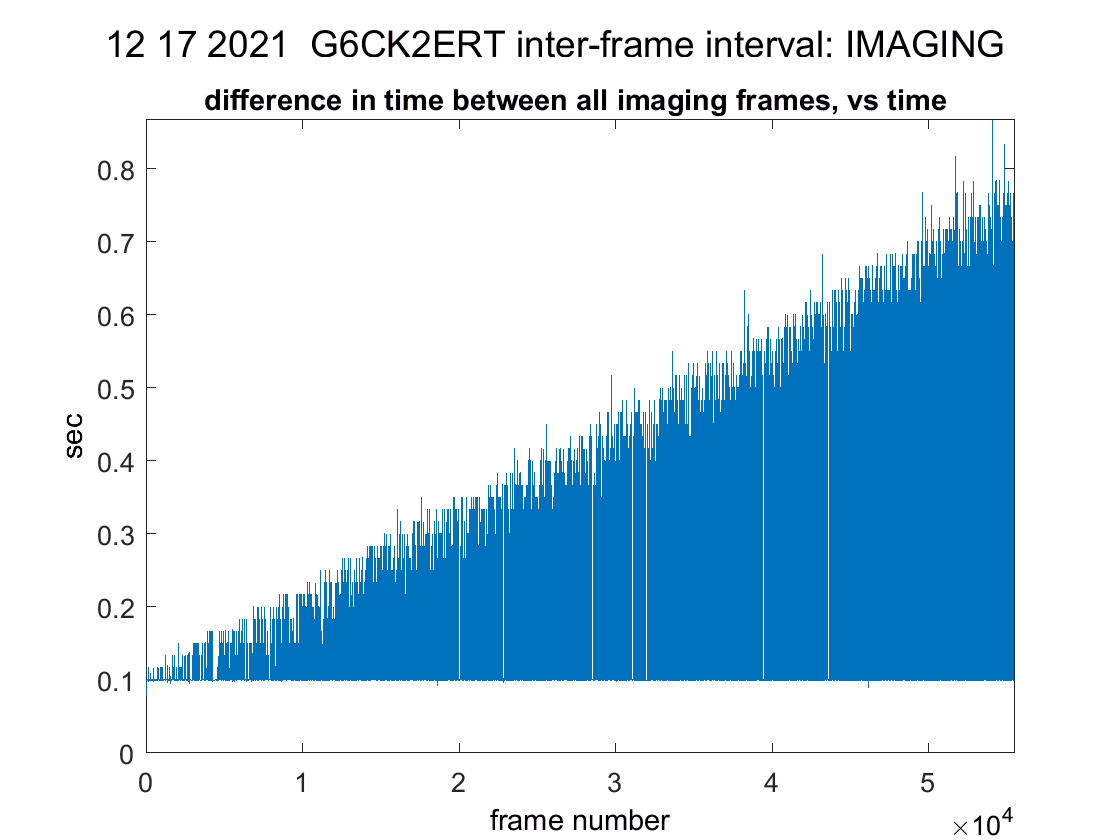

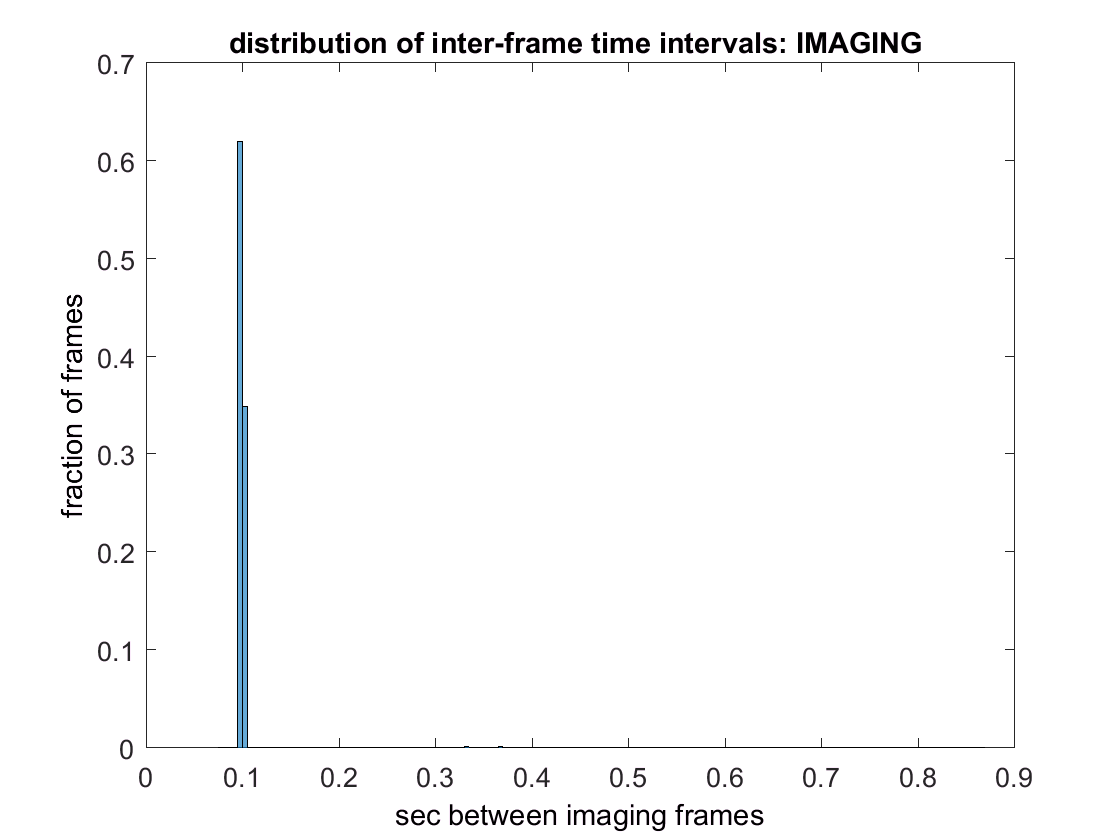

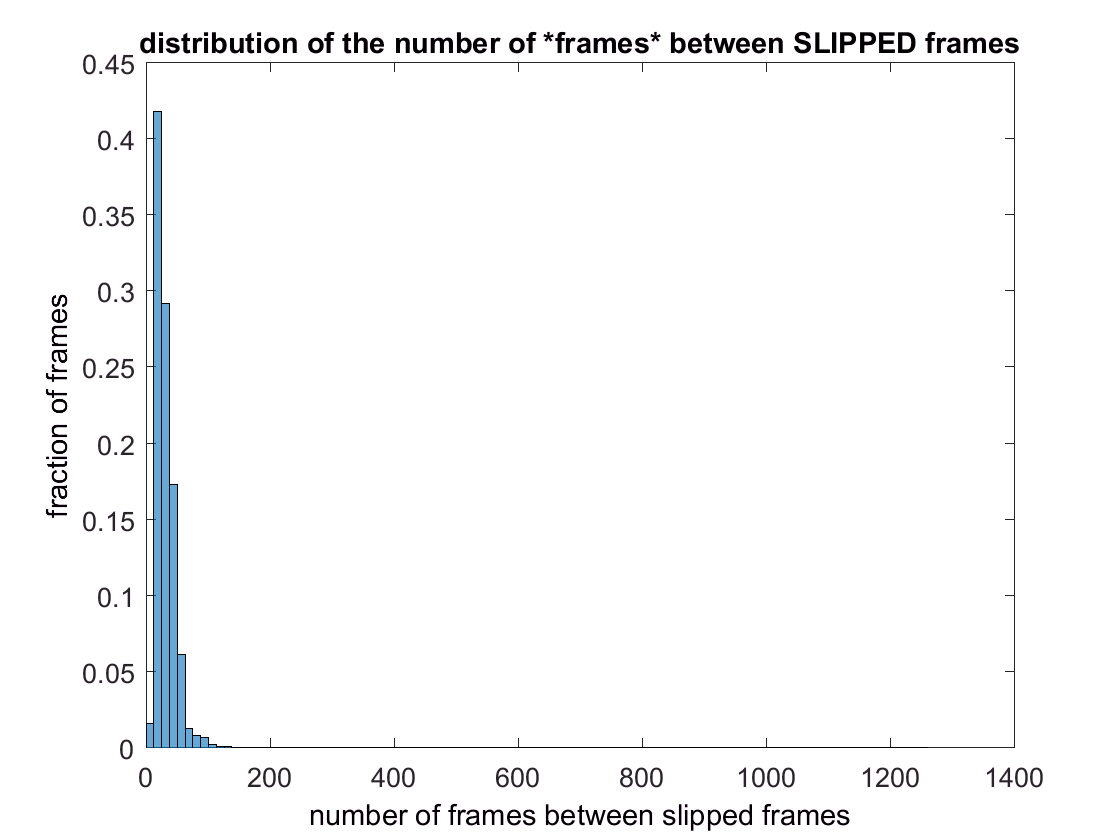

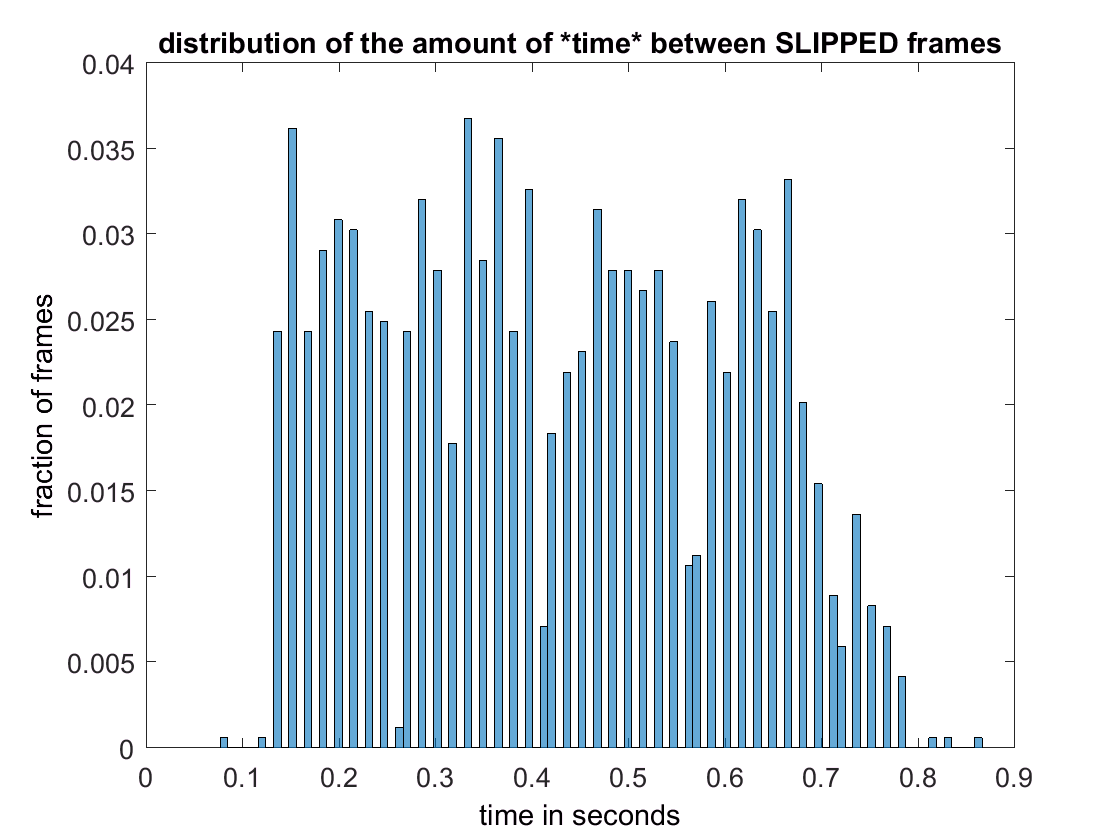

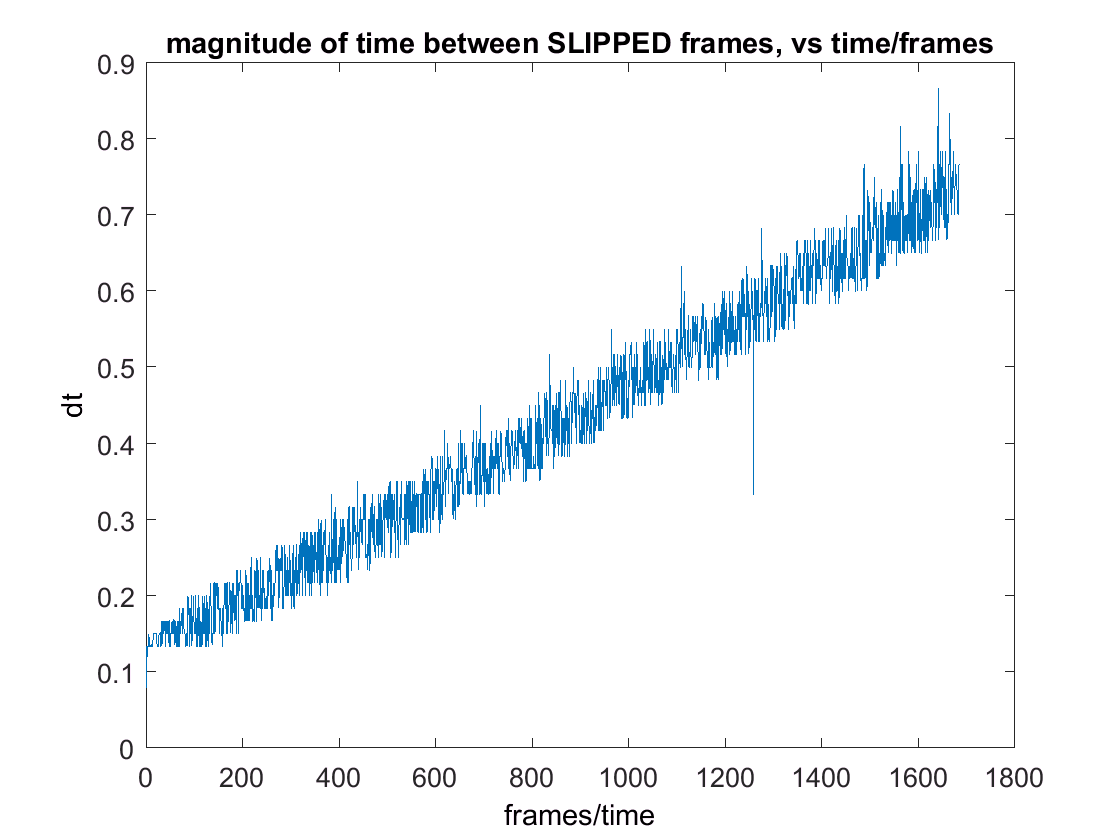

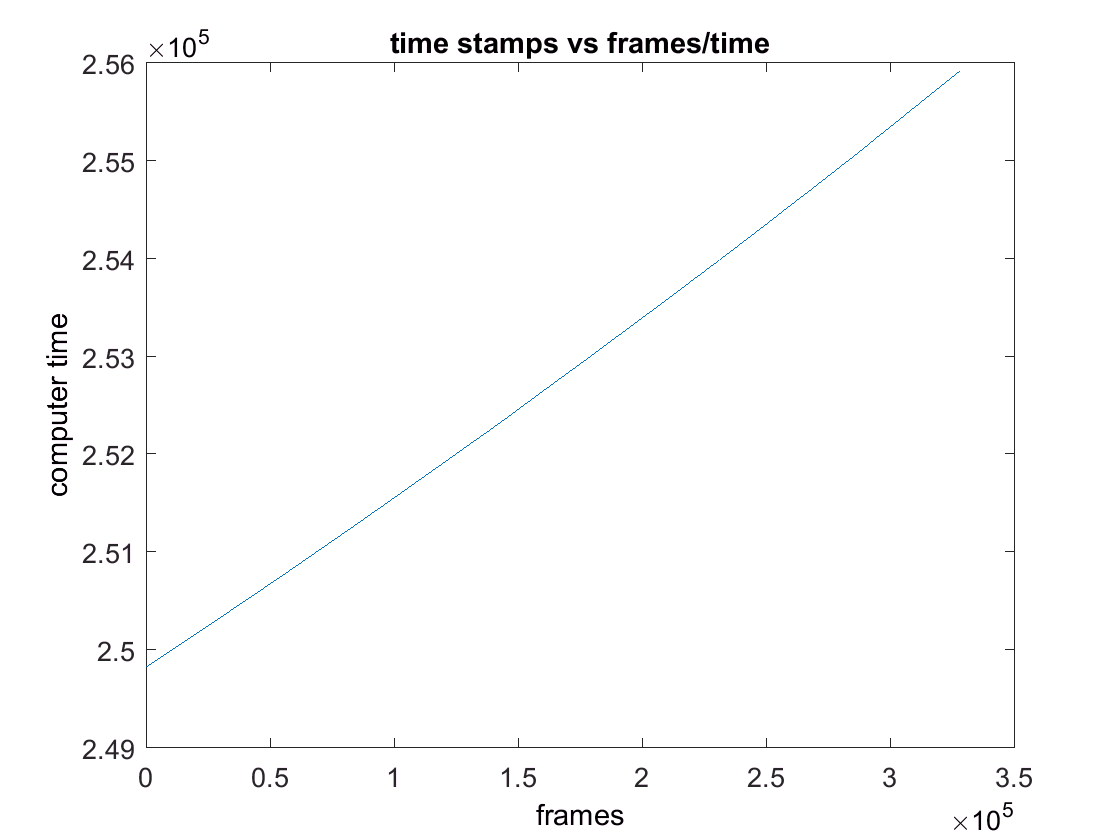

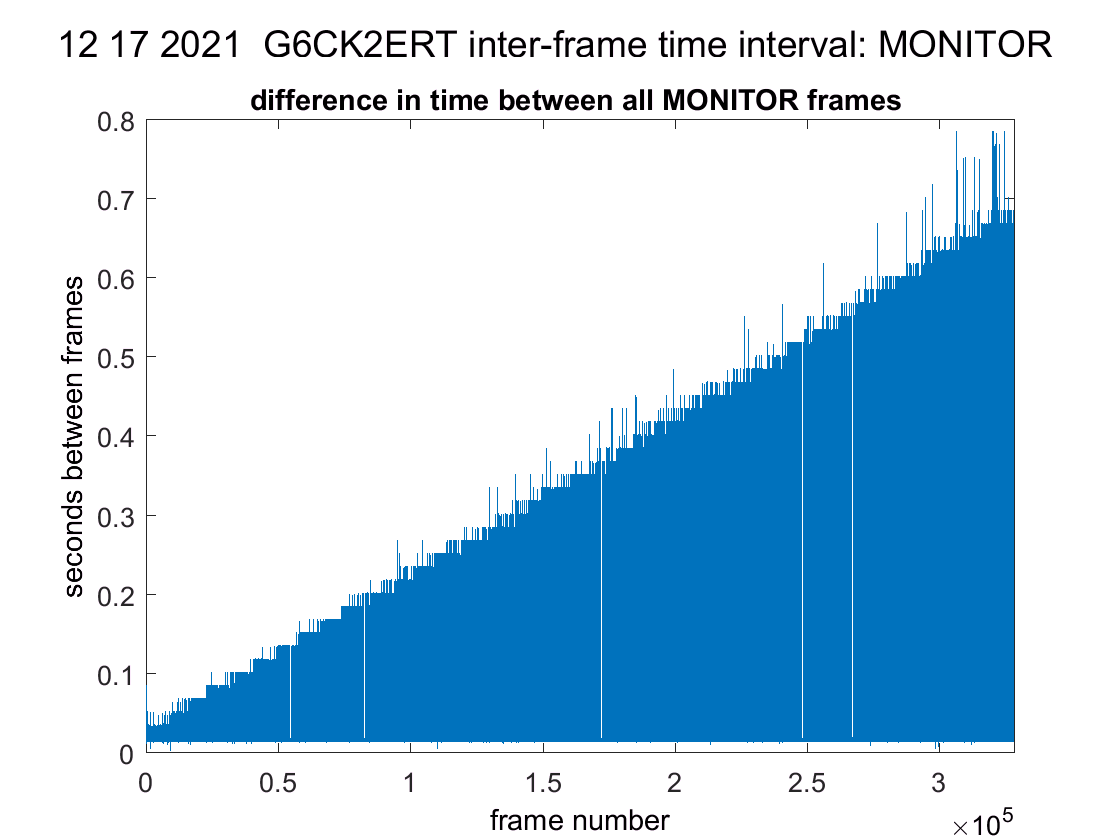

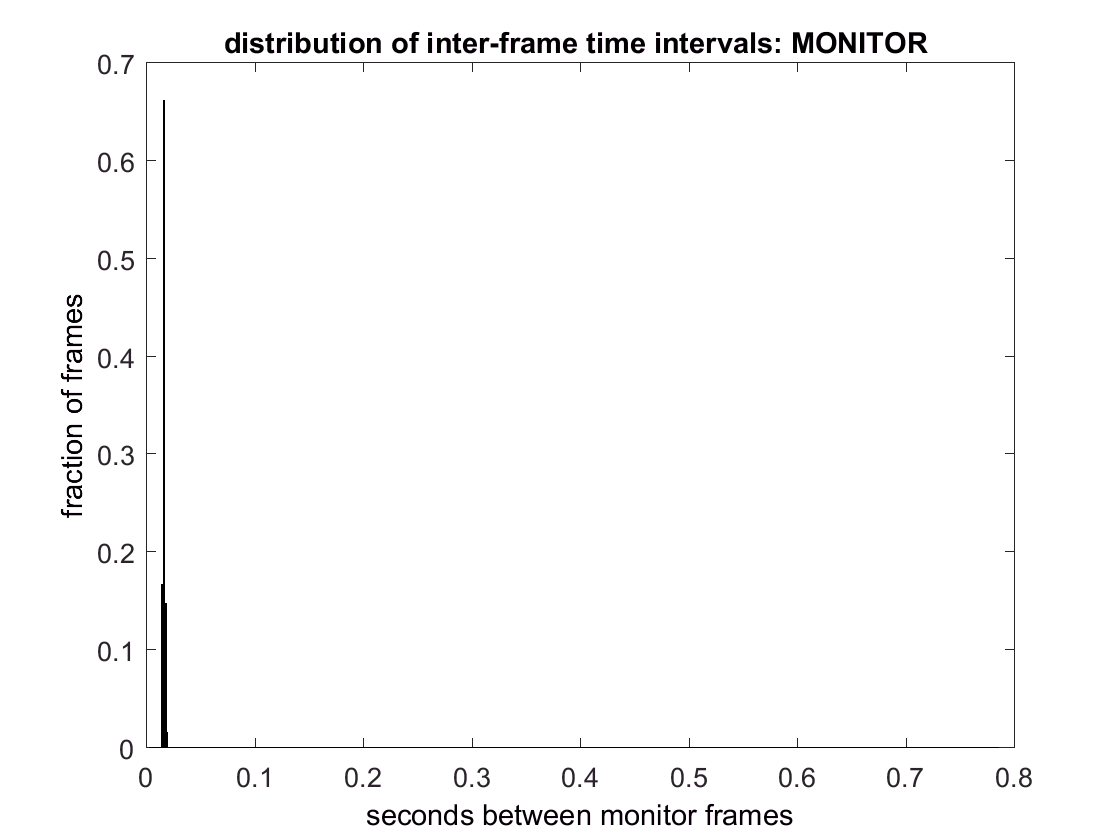

% check imaging & monitor frame rate
[percentSlippedImagingFrames,timeStampsStopAndRespFramesAlltrialsMinusT0,percentSlippedMonitorFrames] = checkImagingAndMonitorFrames(frameT,allStop,allResp,subjName,date);

## CROP FLUORESCENCE MOVIE

numFramesWholeSession = 55465

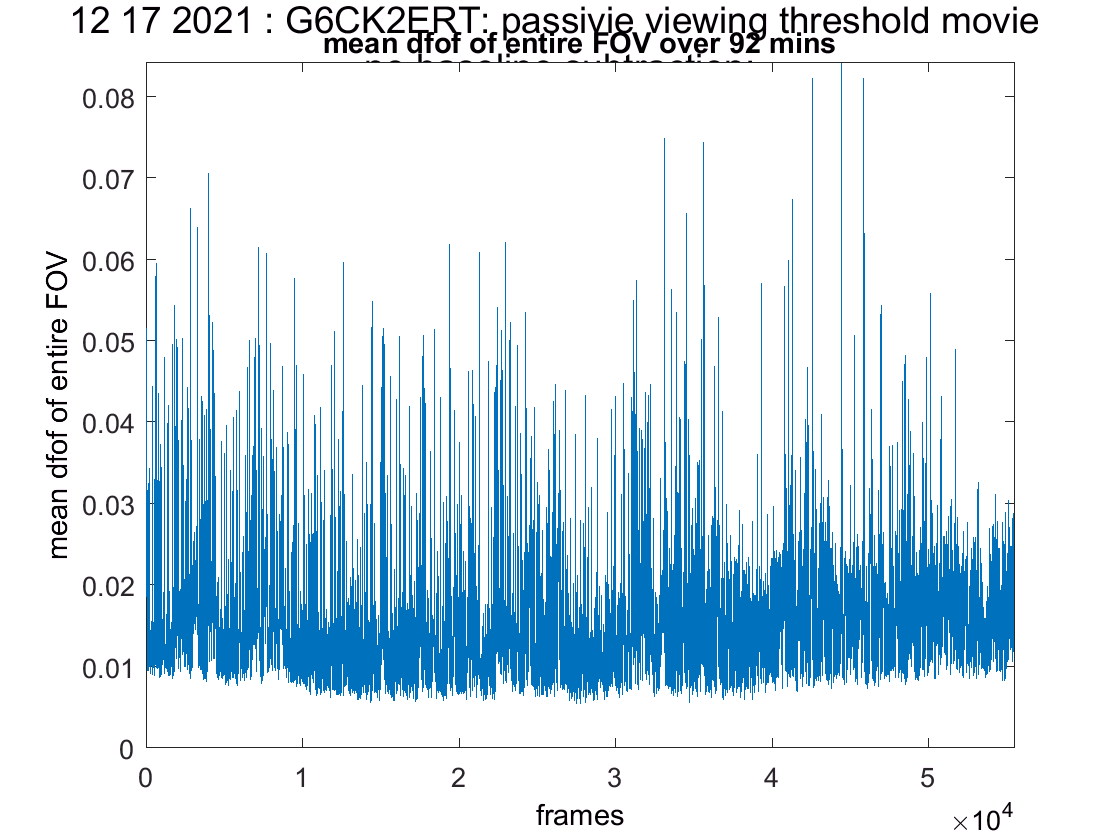

% check broad activity over whole field of view
meanDfEntireFOVvsFrames_wholeSessAnd1min(df,subjName,date);

range =          0    0.0600


colorMapOrNot = 2

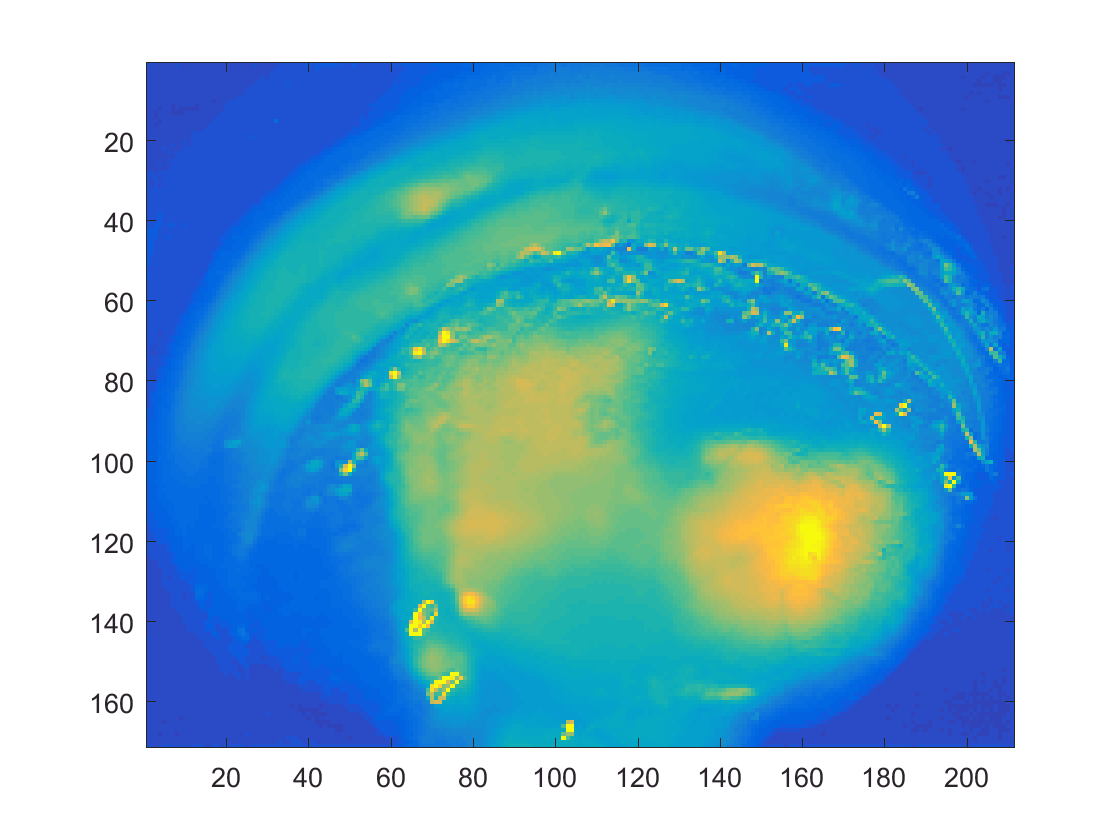

% pick the image/adjust the range on the image to be used for cropping in following step
[range,colorMapOrNot] = pickImageToCrop(df,subjName,date);

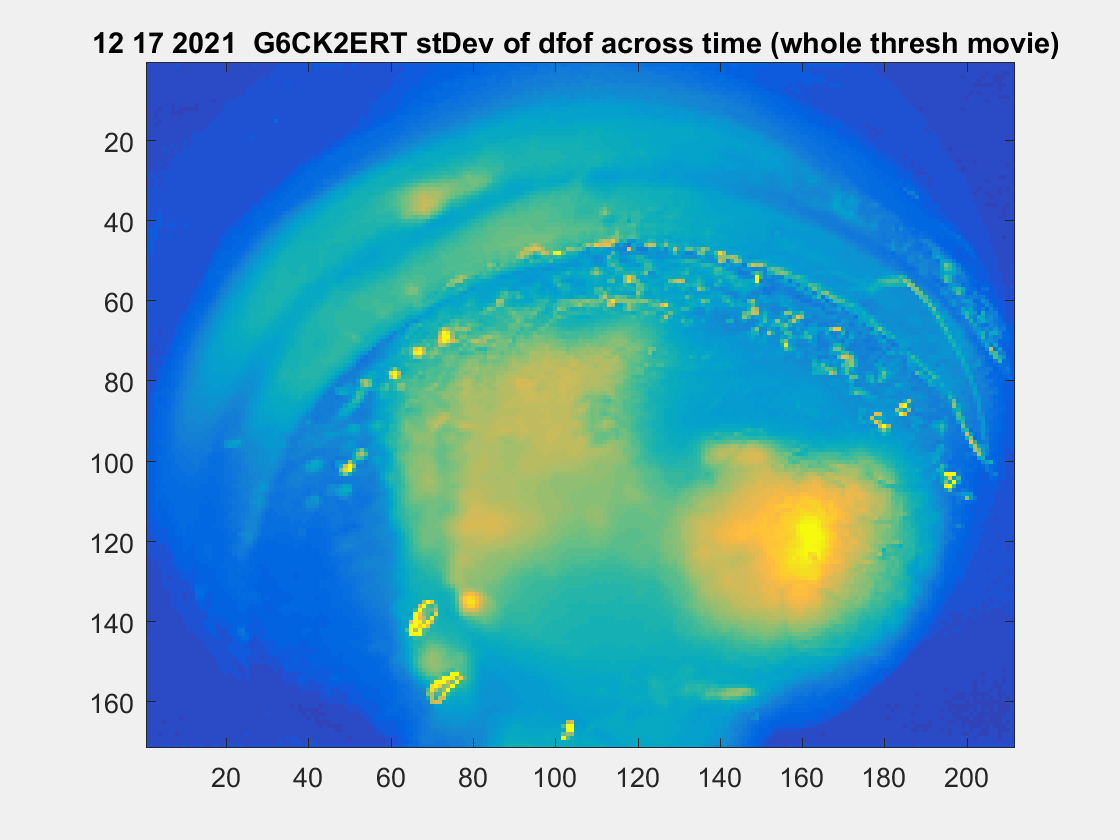

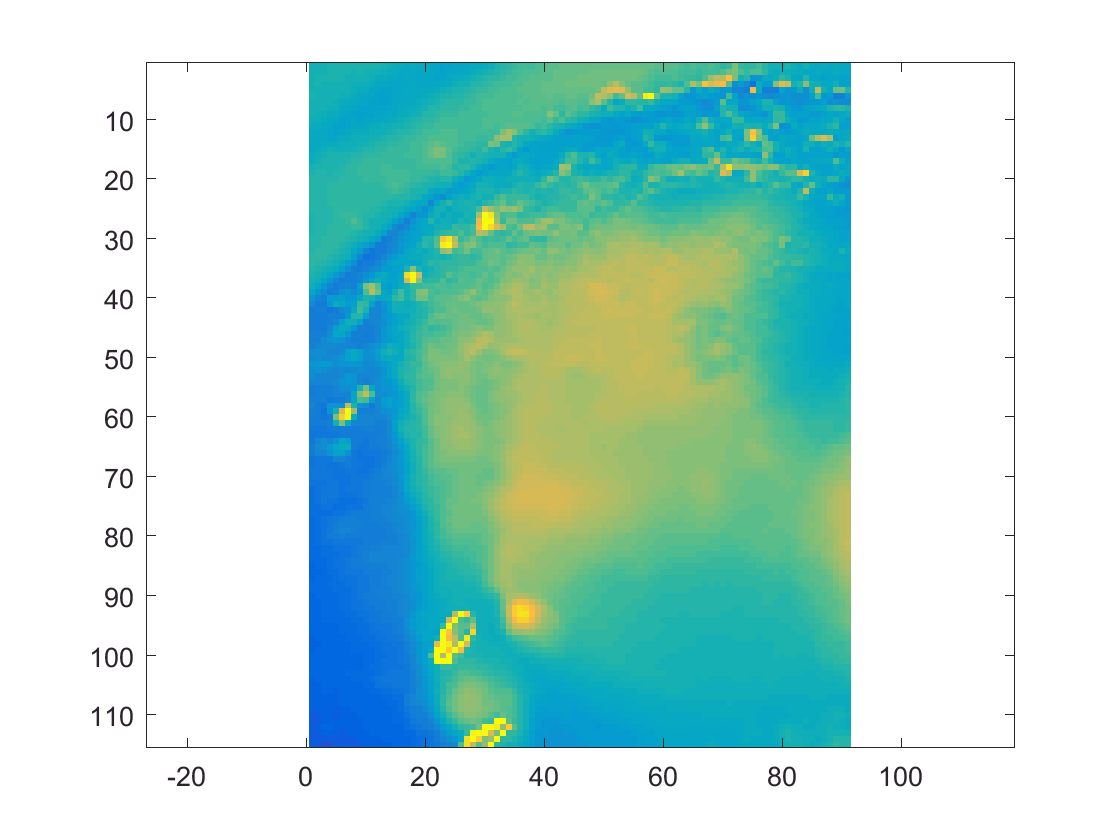

% crop image/movie & show cropped image
[xPtsCrop,yPtsCrop,dfCROP] = doCrop(df,range,colorMapOrNot,date,subjName);

## SEGMENT BY STIM ONSET

% get time of stimulus onsets for each trial
[stimOnsets] = onsetsStimFrames(allStop,allResp);

sizeOfOnsets =            1        1831


% how many early & late trials to filter out? change this in this meta script if need
earliestTrial = 6

earliestTrial = 6

numLateTrialsSubtract = 5

numLateTrialsSubtract = 5

% filter first and last few trials... can change num trials in code
[idxOnsetsMeetsCriteria,filteredStimOnsets] = filterOnsets_removeEarlyAndLateTrials(stimOnsets,earliestTrial,numLateTrialsSubtract);

sizeOnsetsMeetCriteria =            1        1821


% for each trial, get the indicies for the 1st imaging frame that folows the stimulus onset
[onsetImFrames] = onsetImagingFrames(filteredStimOnsets,frameT);

sizeOfOnsetImFrames =            1        1821


% picking pre & post imaging frames for indexing dfCROP into "chunks"

% keeping this in the meta script for now b/c i want it easily changeable
numPreStimFrames = 3

numPreStimFrames = 3

numPostStimFrames = 14

numPostStimFrames = 14

% make onsetDf variable

% use the indicies for the 1st imaging frame follwing stimulus onset, 
% plus the num pre & post frames defined earlier in this script,
% to index into dF % take 'chunks' of video around each stim onset
[onsetDf] = makeOnsetDf(onsetImFrames,dfCROP,numPreStimFrames,numPostStimFrames);

sizeOfOnsetDf =          115          91          18        1821


## GET STIM PARAMS for LOOPS and LEGENDS

% make vector of stim conditions in order of presentation/trial,
% & list of unique stim params (for looping)
[conOrderedByTrialMeetCriteria,uniqueContrasts,durOrderedByTrialMeetCriteria,uniqueDurations,conAndDurOrderedByTrialMeetCriteria] = getStimParamsNtrialConds(stimDetails,trialCond,idxOnsetsMeetsCriteria)

conOrderedByTrialMeetCriteria =     0.0300    0.0300    0.5000         0    0.2500    0.2500    0.2500    0.2500    0.1250         0    0.2500    0.2500    0.5000    0.0625    0.0300    0.0300    1.0000    1.0000    1.0000         0    1.0000    1.0000    0.5000    0.0300    0.0300    0.0625         0         0         0         0         0    0.1250    0.1250    0.1250    0.0625    0.0300    0.0300    0.5000    1.0000         0    0.2500    0.0625    0.2500    0.2500    0.0625         0    0.5000    0.5000    1.0000    1.0000


uniqueContrasts =          0    0.0300    0.0625    0.1250    0.2500    0.5000    1.0000


durOrderedByTrialMeetCriteria =      6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6     6


uniqueDurations = 6

conAndDurOrderedByTrialMeetCriteria =     0.0300    0.0300    0.5000         0    0.2500    0.2500    0.2500    0.2500    0.1250         0    0.2500    0.2500    0.5000    0.0625    0.0300    0.0300    1.0000    1.0000    1.0000         0    1.0000    1.0000    0.5000    0.0300    0.0300    0.0625         0         0         0         0         0    0.1250    0.1250    0.1250    0.0625    0.0300    0.0300    0.5000    1.0000         0    0.2500    0.0625    0.2500    0.2500    0.0625         0    0.5000    0.5000    1.0000    1.0000
    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000    6.0000 

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LM'    'RL'    'AM'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend

durs4Legend =     '6'


## PICK BASELINE FRAMES

baselineIdx =      1     2     3


stimOnsetFrame = 4

stimOnsetFrame = 4

baselineIdx =      1     2     3


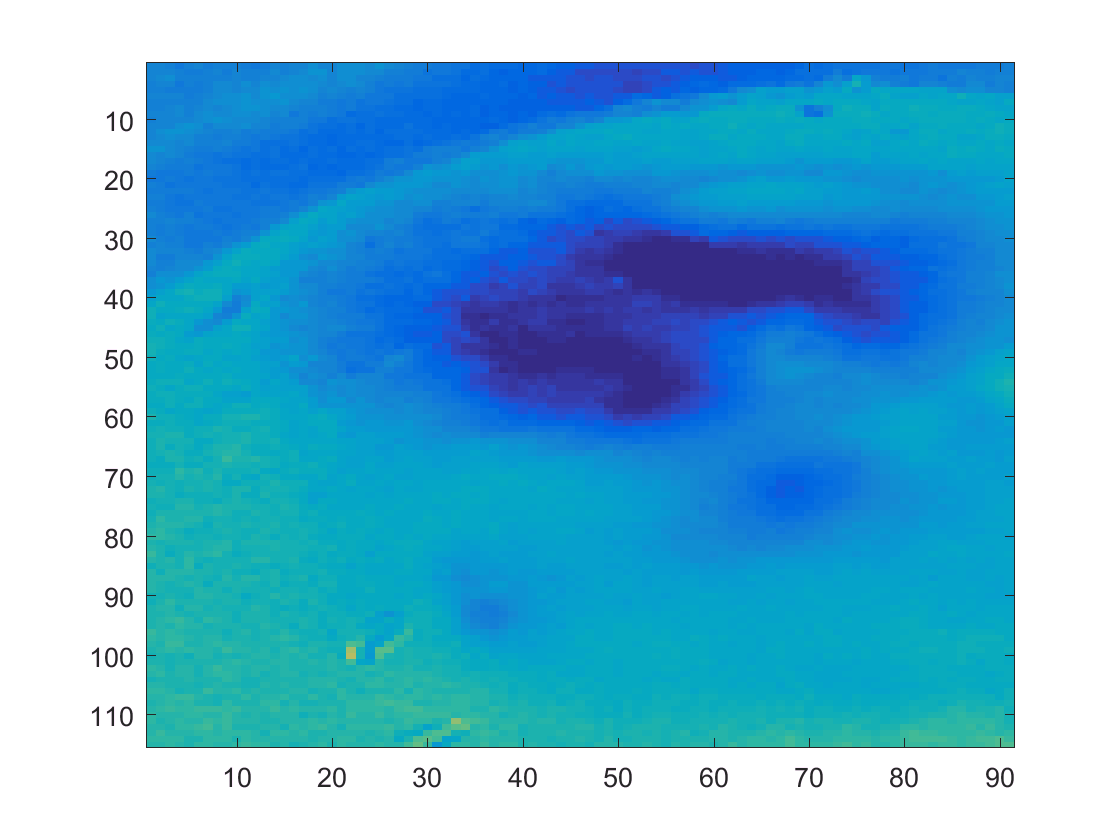

% pick the baseline indicies, show the mean baseline image, subtract from pix wise onsetDf
% images to demonstrate that these baseline indicies are appropriate. Diagnostic figures. 
[stimOnsetFrame,baselineIdx] = pickBaselineIdx(numPreStimFrames,conOrderedByTrialMeetCriteria,uniqueContrasts,date,subjName,onsetDf) 

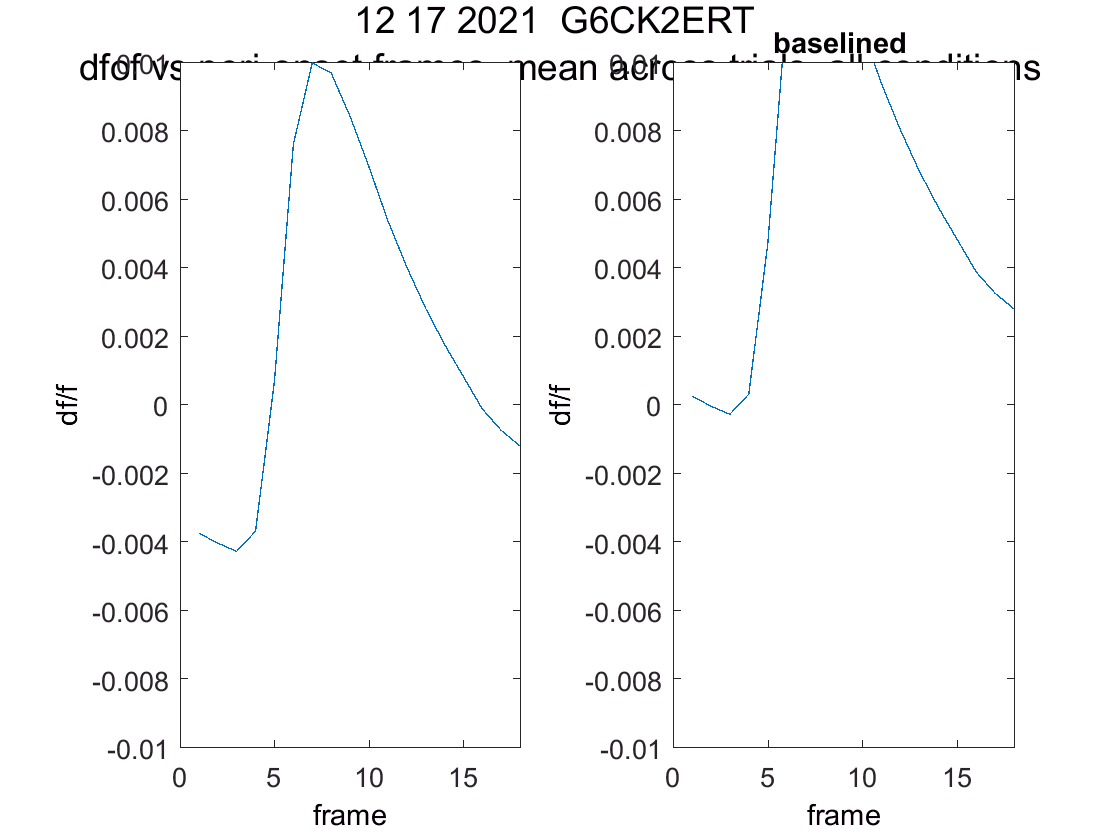

% now do similar - show that subtracting mean basline values works as expected, but
% plot mean (over trials) df of entire (cropped) imageing view vs frames (regular graph, not pixel wise)
plotPrePostBaselineOnsetDfVsFrames(onsetDf,date,subjName,baselineIdx);

range =          0    0.0600


colorMapOrNot = 1

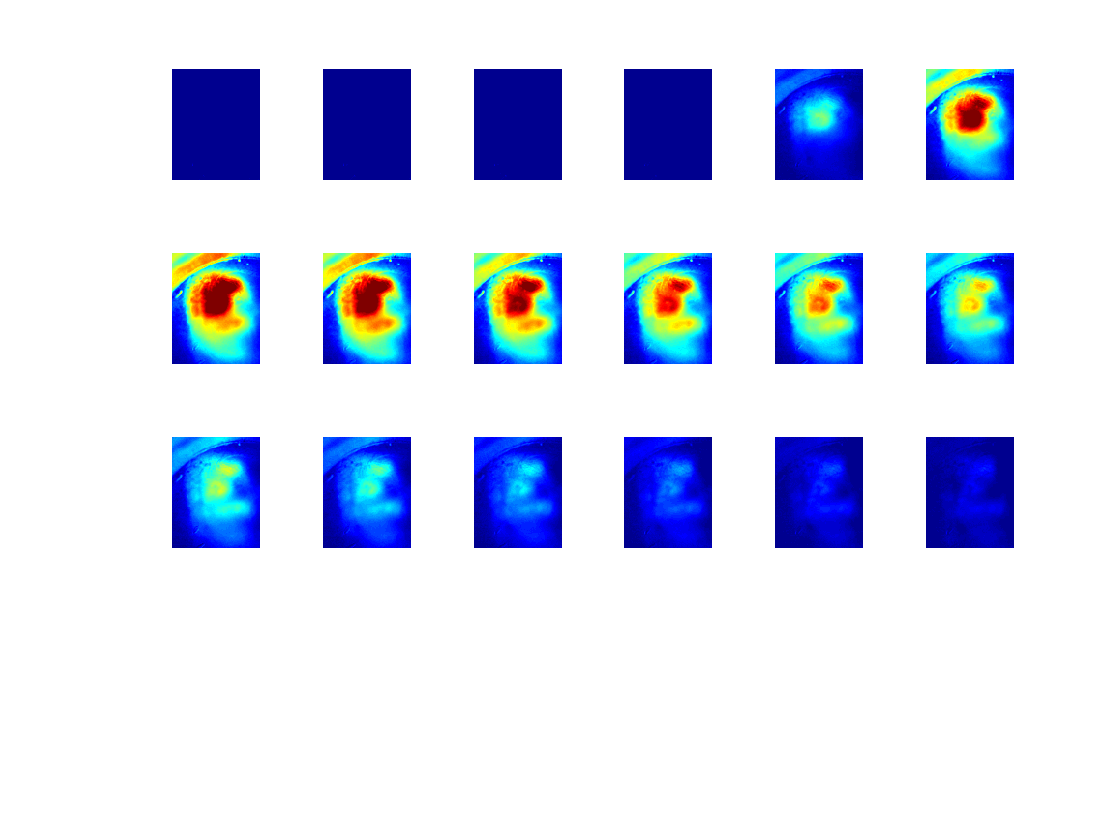

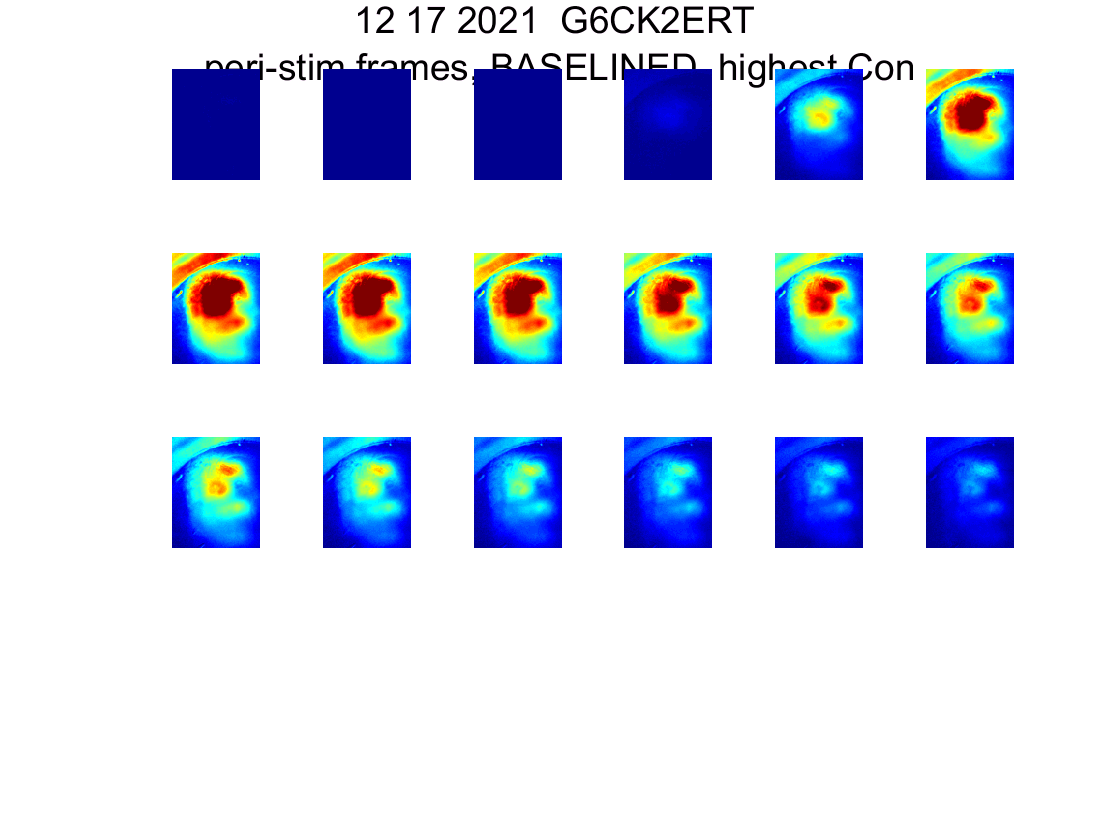

% show pix wise peri stim pre & post baseline-ing
showPixWisePeriStimPrePostBaseline(conOrderedByTrialMeetCriteria,uniqueContrasts,onsetDf,baselineIdx,date,subjName)

## MAKE PERI-STIM ACTIVITY MAPS PER CON & PER DUR

range =          0    0.0500


colorMapOrNot = 2

frameRange =      4     5     6     7     8     9    10    11    12    13    14    15    16    17    18


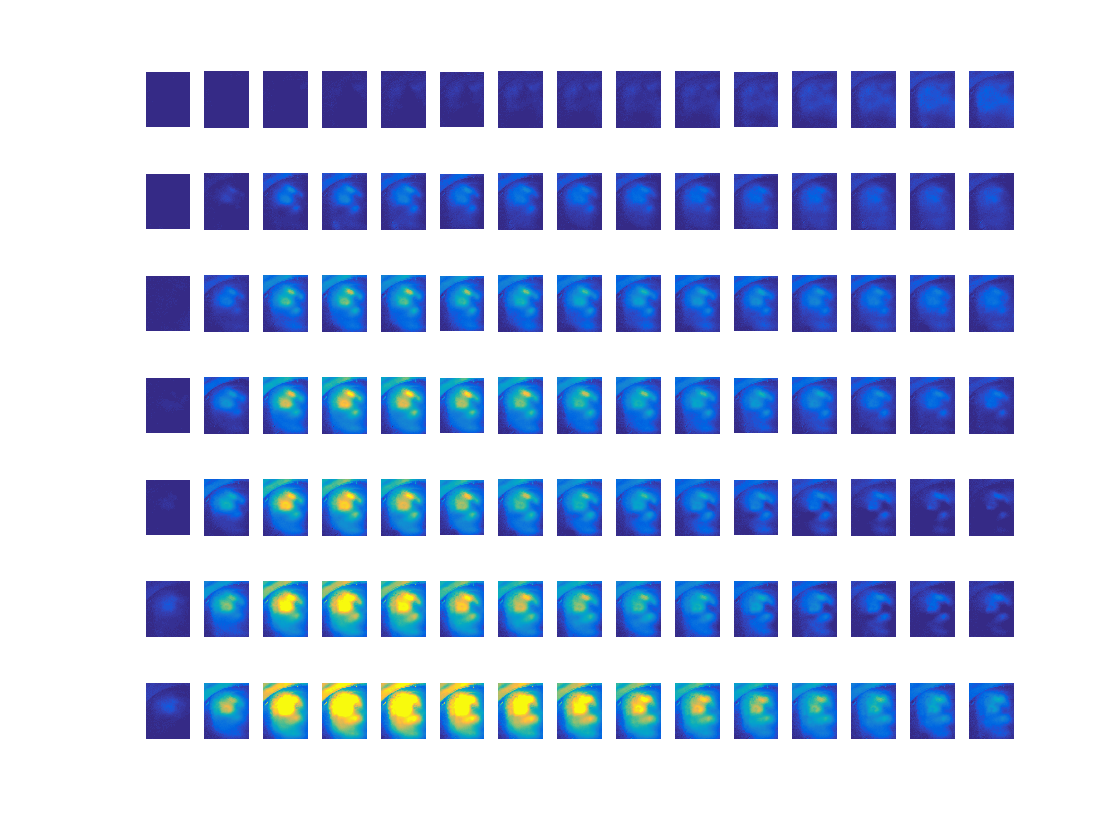

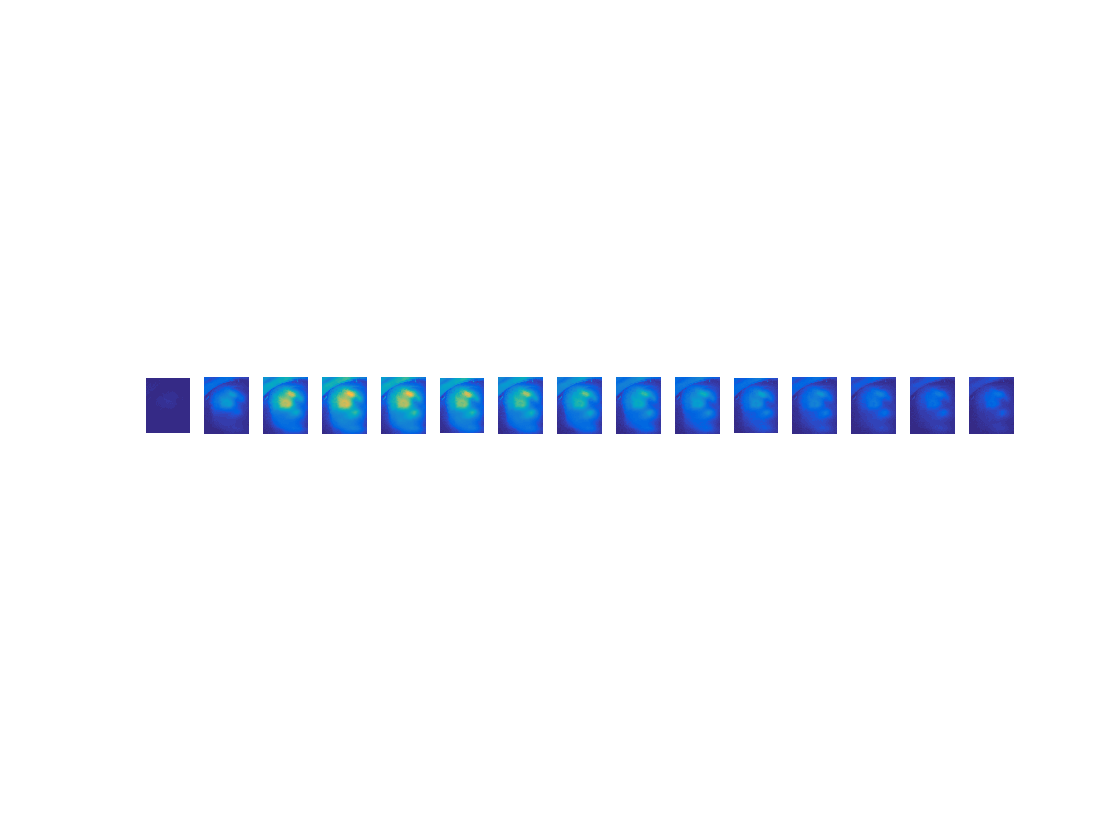

% pix wise peri stim  per stim cond (con only then dur only)
showPixWiseByStimConds(stimOnsetFrame,date,subjName,uniqueContrasts,conOrderedByTrialMeetCriteria,onsetDf,baselineIdx,uniqueDurations,durOrderedByTrialMeetCriteria);

## PEAK ACTIVITY  MAPS PER STIM COND

% define peak activity frames (can change num frames in code, default is 10 frames post-stim onset frame)
numPeakFrames = 2;
[peakFrameIdx] = pickPeakFrames(stimOnsetFrame+1,numPeakFrames)

stimOnsetFrame = 5

peakFrameIdx =      6     7


range =          0    0.0500


colorMapOrNot = 2

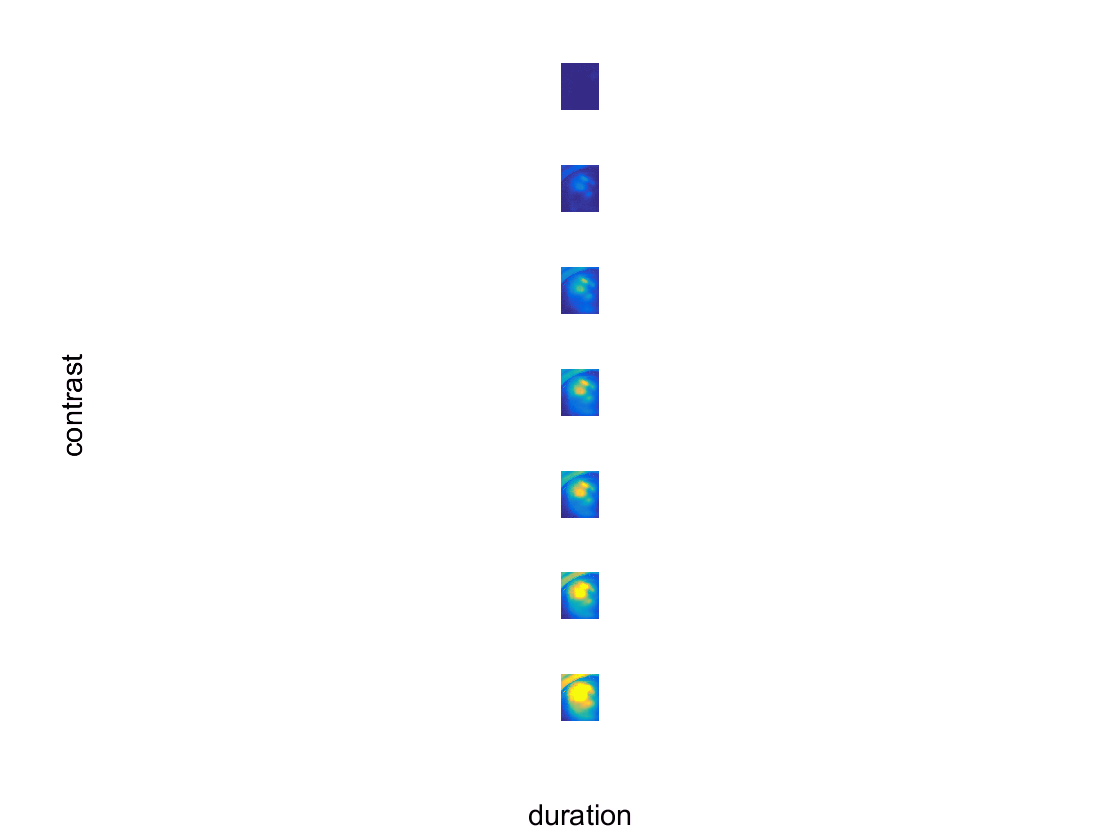

% show peak pix wise activity for each stim condition (con/dur combo)
showPixWisePeakActivityPerStimCond(date,subjName,uniqueContrasts,uniqueDurations,conAndDurOrderedByTrialMeetCriteria,peakFrameIdx,onsetDf,baselineIdx);

## POINTS FOR ANALYSIS

range =          0    0.0800


colorMapOrNot = 1

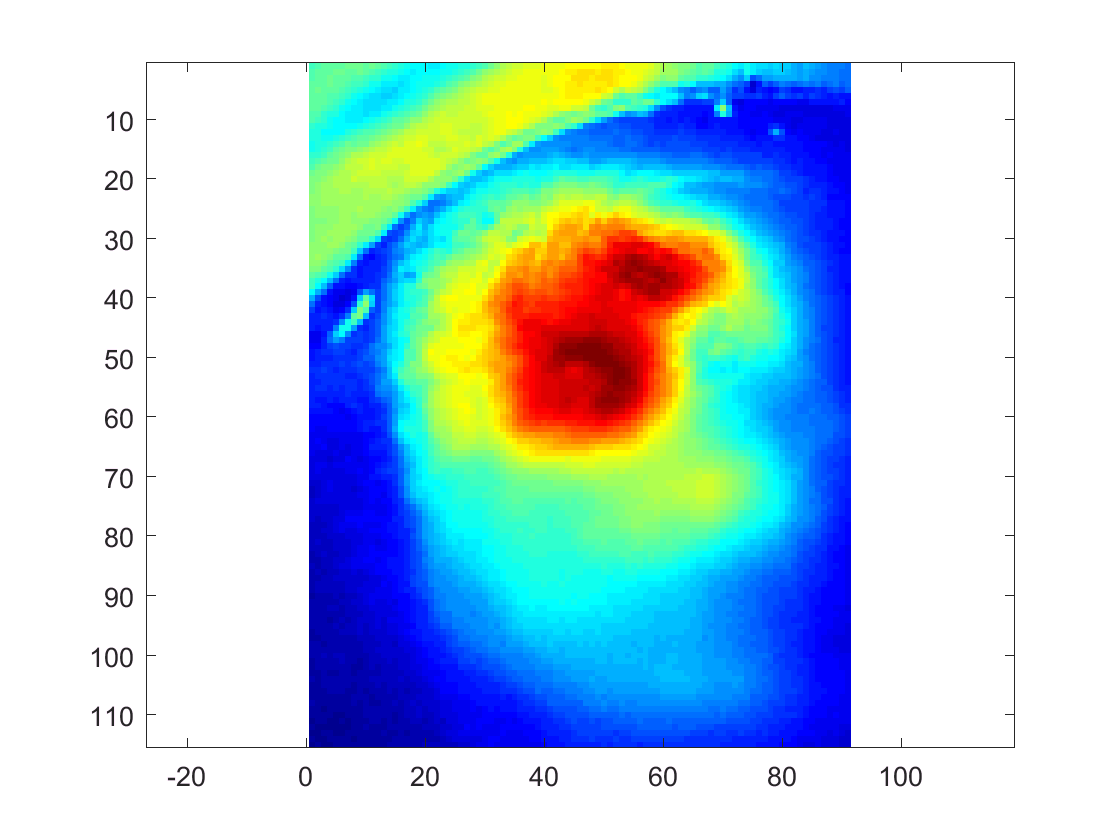

% Pick the image to be used to pick points in visual areas in next step
[baselinedActIm,range,colorMapOrNot] = pickPeakActIm4Points(conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations,peakFrameIdx,onsetDf,baselineIdx);

% Make 3 IMAGE to help idenitfy visual areas & blood vessels...
% first run do_topo, which needs the recording session to be un-commented in batch file
formatSpec = '%s%s%s';
dateNoSpaces = sprintf(formatSpec,date(1:2),date(4:5),date(9:10))
[meanpolar,ypts,xpts] = do_topo(subjName,dateNoSpaces)

% % now SHOW the fig (despite that the name of the function says)
% % CHANGE the tif file/folder path in ehere each time
%[tifPic] = pickVisAreaPts3figs(meanpolar,ypts,xpts,baselinedActIm,df,range);

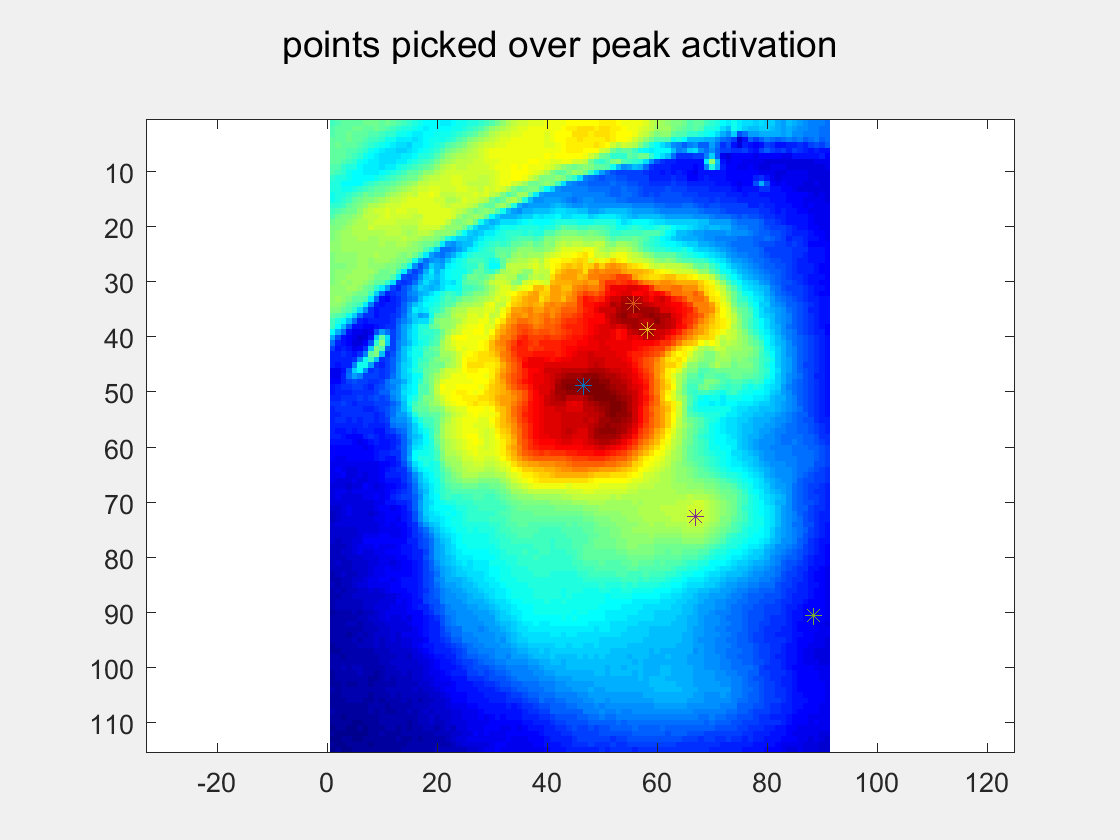

% actually pick the points
[xPickedPts,yPickedPts] = pickVisAreaPts(baselinedActIm,range,colorMapOrNot);

% make PTSdfof - this time I took the *mean over 25 pix squared (5x5 pix area)* for each point
[RoundXpts,RoundYpts,PTSdfof] = makePTSdfof(xPickedPts,yPickedPts,onsetDf,range,colorMapOrNot);

sizePTSdfof =            5          18        1821


## GET NON-SEGMENTED V1 DF TRACE FOR ENTIRE RECORDING

## (for pupil analysis)

% note that there is no way to baseline a trace for the entire recording...

clear dfofV1Point
dfofV1Point(1,:,:) = dfCROP(RoundXpts(1),RoundYpts(1),:,:);

sizeDfofV1Point = size(dfofV1Point)

## RUNNING ANALYSIS

sizeOf_allXYcursorCoordinatesStopAndRespFramesAlltrials =            2      328182


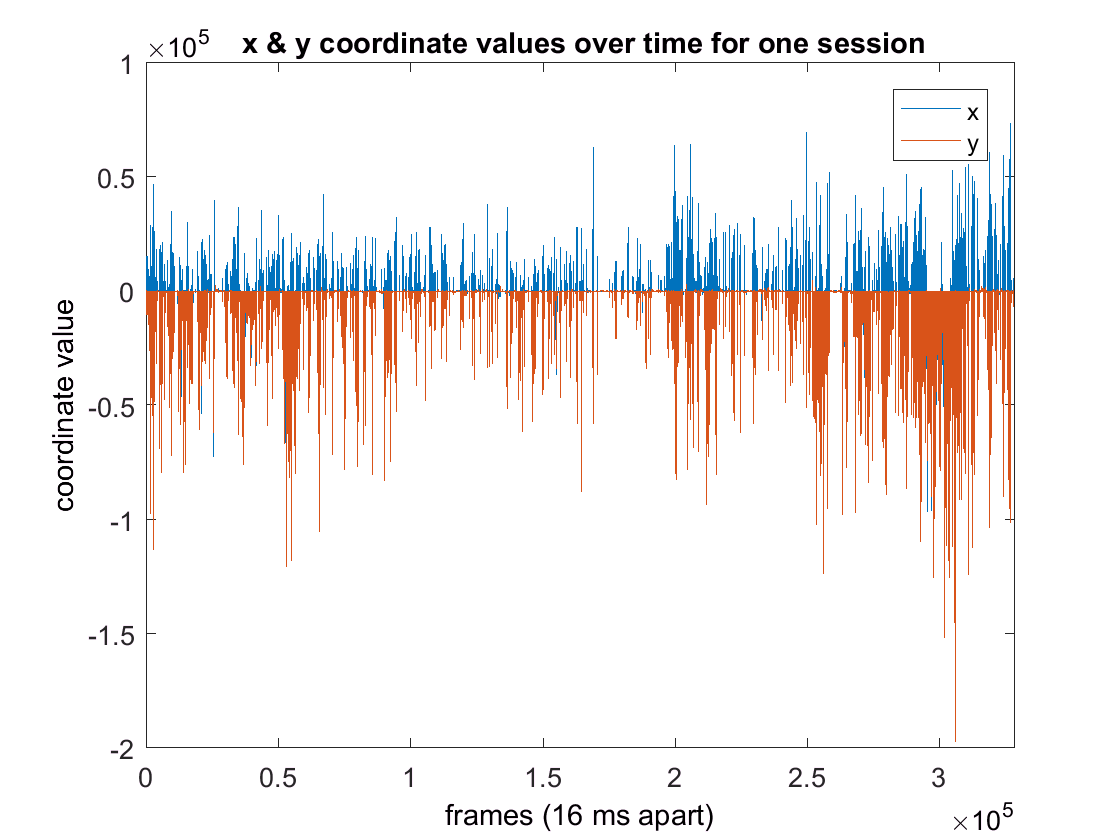

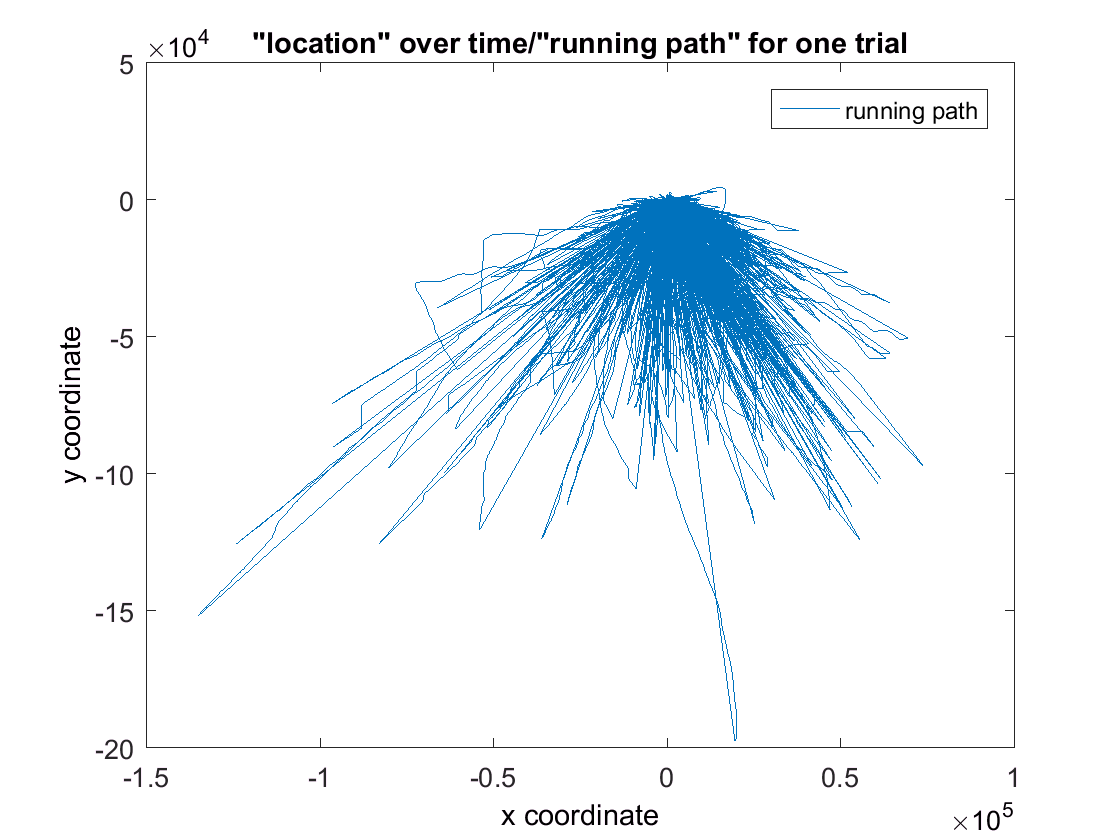

% x & y coordinates, run path
[allXYcursorCoordinatesStopAndRespFramesAlltrials] = stitchBackCursorCoordinatesForAllTrialsAndFrames(allStop,allResp);

numTrialsInSession = 1831

sizeOf_meanSpeedAllTrials =            1        1831


numTrials = 1831

numBins = 10

numTrialsOverThresh = 1073

percentTrialsOverThresh = 58.6019

numStatTrials = 758

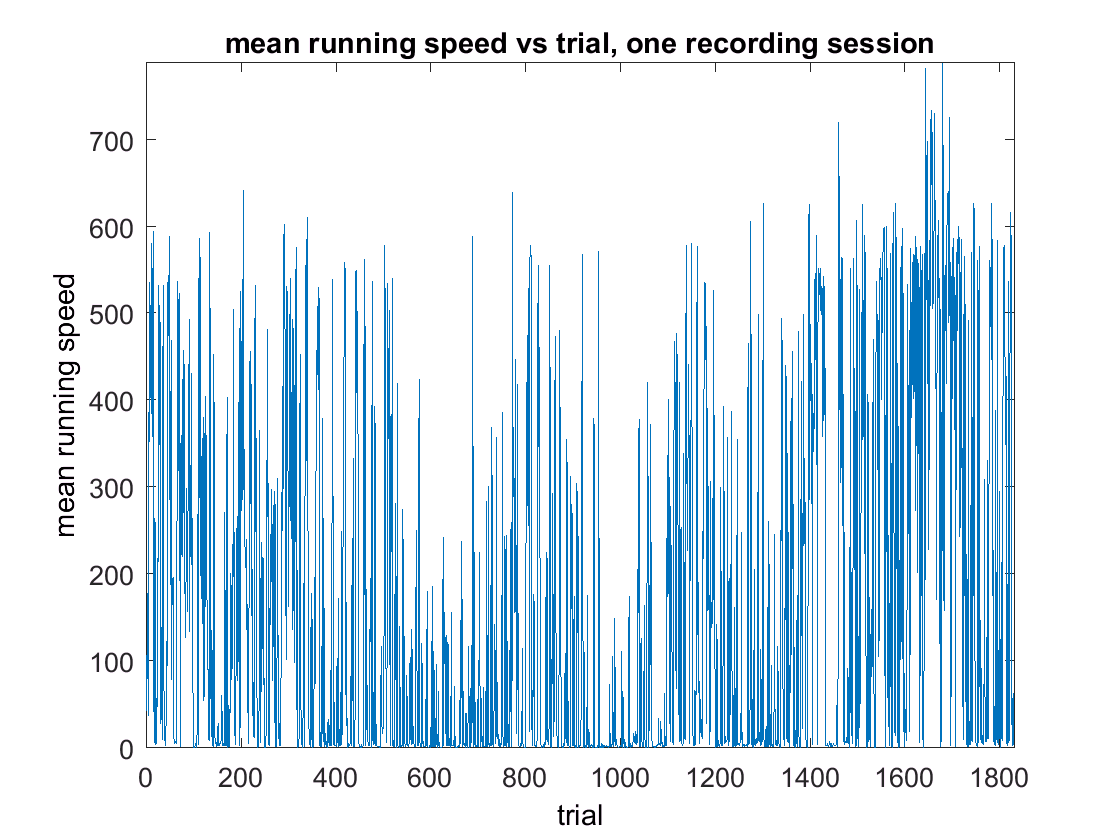

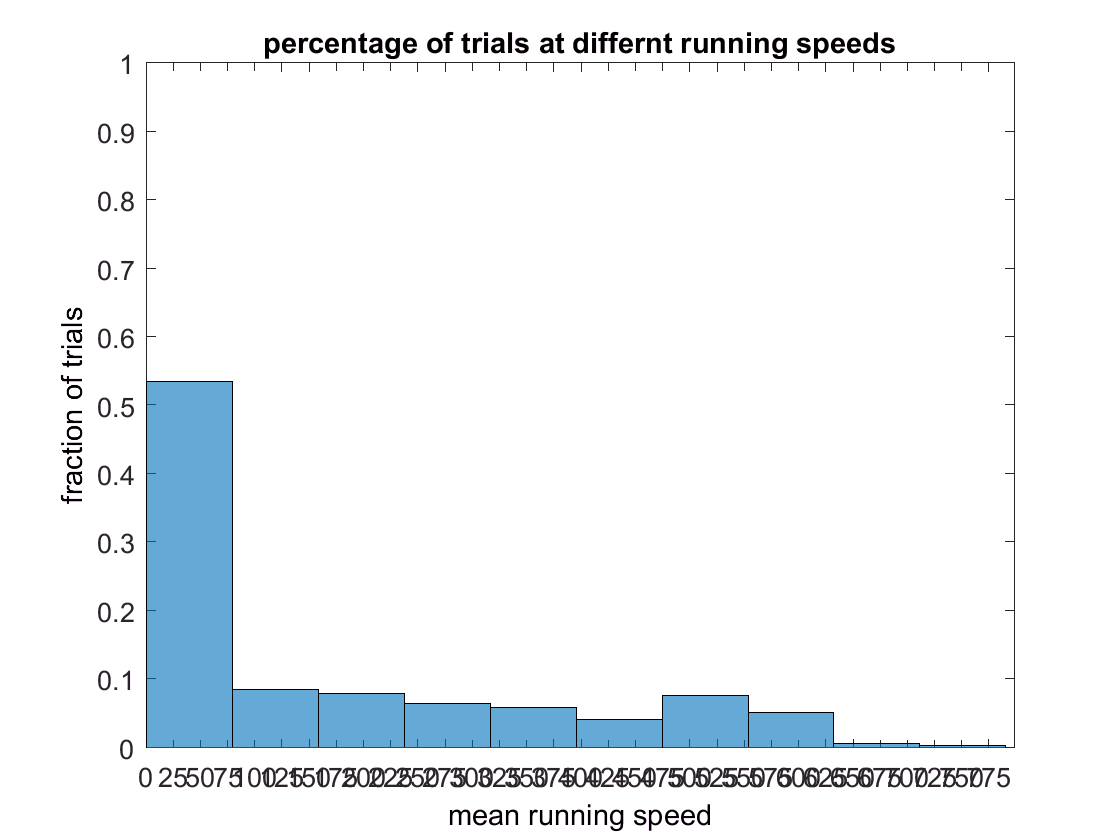

% calculate mean run speed for each trial
runThresh = 10;
[meanSpeedAllTrials,idxRunTrials,idxStatTrials] = calcMeanRunSpeedAllTrials(allStop,allResp,runThresh);

% FILTER first and last few trials... can change num trials in code
[runIdxOnsetsMeetsCriteria,meanSpeedAllTrials] = filterOnsets_removeEarlyAndLateTrials(meanSpeedAllTrials,earliestTrial,numLateTrialsSubtract);

sizeOnsetsMeetCriteria =            1        1821


sizemeanSpeedAllTrials = size(meanSpeedAllTrials)

sizemeanSpeedAllTrials =            1        1821


## PUPIL ANALYSIS

% MANUALLY LOAD DLC/python PUPIL TRACKING data


% plot pupil diamter over time (in pix)
figure
plot(longaxis)
ylabel('diameter(pix)')
xlabel('frames (60 Hz)')
title('pupil diameter over time')

sizeLongAxis = size(longaxis,2)
sizeDf = size(df,3)


% ONSET SEGMENTING - 
% line up pupil dimater trace with V1 dfof trace for each
% stim onset chunk

% Index long axis with the values in onsetFrame, 
% which are the indicies of imaging frames at the onset of a trial

% long axis is downsampled to 10Hz so time stamps are not needed,
% only imagaing frame indicies

clear o
for o = 1:length(onsetImFrames)
    
    % then select only the imaging frames right before & after the onset imaging frame of each stim
    eachOnsetPupil = longaxis(1,onsetImFrames(o)-numPreStimFrames:onsetImFrames(o)+numPostStimFrames);
    
    allOnsetPupils(o,:) = eachOnsetPupil;

end

%sizeOfEachOnsetPupil = size(eachOnsetPupil)
sizeOfAllOnsetPupils = size(allOnsetPupils)


% plot one trial
figure
plot(allOnsetPupils(400,:))


% get mean pupil diamter for each trial

clear p 

for p = 1:length(allOnsetPupils)
    
    meanPupilDiameterEachTrial = mean(allOnsetPupils(p,:));
    meanPupilDiameterAllTrials(1,p) = meanPupilDiameterEachTrial;
    
end

sizeMeanPupilDiameterAllTrials = size(meanPupilDiameterAllTrials)

% noramlize pupil diamter to miniumum pupil diameter
meanPupilDiameterAllTrials = meanPupilDiameterAllTrials-min(meanPupilDiameterAllTrials);


% frequency of pupil diameter sizes
figure
histogram(meanPupilDiameterAllTrials,'Normalization','probability')
title('frequency of pupil diameters')
xlabel('pupil diamater values')
ylabel('fraction of trials')


% DEFINE THRESHOLD
threshold = 12


% DEFINE LARGE VS SMALL VS MED ETC PUPIL TRIALS
% indicies for trials that meet our threshold
% USE to INDEX trials in PTSdfof onset CHUNKS

idxLargePupilTrials = find(meanPupilDiameterAllTrials>=threshold);
idxSmallPupilTrials = find(meanPupilDiameterAllTrials<=threshold);

numTrials = length(meanPupilDiameterAllTrials)
numTrialsOverThresh = length(idxLargePupilTrials)
numTrialsUnderThresh = length(idxSmallPupilTrials)
percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100


## RUN & PUPIL TOGETHER

%meanPupilDiameterAllTrials needs to have the first & last 

x_axis = 1:length(meanSpeedAllTrials);
figure
subplot(2,1,1)
plot(x_axis,meanSpeedAllTrials,'r')
title('run speed')
xlim([0 length(x_axis)])

x_axis = 1:length(meanPupilDiameterAllTrials);

subplot(2,1,2)
plot(x_axis,meanPupilDiameterAllTrials,'k')
hold on 

% thresh line
clear y
y(1,1:length(meanPupilDiameterAllTrials)) = threshold;

plot(1:length(y),y,'g')
title('pupil diameter')
xlim([0 length(meanPupilDiameterAllTrials)])


% above but smaller time range

aFewTrialsMeanSpeedAllTrials = meanSpeedAllTrials(1,900:1000)
aFewTrialsMeanPupilDiameterAllTrials = meanPupilDiameterAllTrials(1,900:1000)

x_axis = 1:length(aFewTrialsMeanSpeedAllTrials);

figure
subplot(2,1,1)
plot(x_axis,aFewTrialsMeanSpeedAllTrials,'r')
title('run speed')
xlim([0 length(aFewTrialsMeanSpeedAllTrials)])

subplot(2,1,2)
plot(x_axis,aFewTrialsMeanPupilDiameterAllTrials,'k')
hold on 
subplot(2,1,2)
clear y
y(1,1:length(aFewTrialsMeanPupilDiameterAllTrials)) = 12;
plot(1:length(aFewTrialsMeanPupilDiameterAllTrials),y,'g')
title('pupil diameter')
xlim([0 length(aFewTrialsMeanSpeedAllTrials)])


% SCATTER RUN VS PUP

figure
scatter(meanSpeedAllTrials,meanPupilDiameterAllTrials)
xlabel('run speed (pix)')
ylabel('pupil diameter (pix)')


## SAVE INDIVIDUAL VARS FOR GROUP/REST OF ANALYSIS

% ** NAVIGATE to correct folder **

% save('081321_EE124LT_vars4IndAndGroupAnalyses.mat',...
%     'stimDetails','subjData','trialCond','subjName','date',...
%     'frameT','numPreStimFrames','numPostStimFrames','onsetImFrames','onsetDf',...
%     'idxOnsetsMeetsCriteria','peakFrameIdx','stimOnsetFrame','baselineIdx',...
%     'baselinedActIm','xPickedPts','yPickedPts','RoundXpts','RoundYpts',...
%     'PTSdfof','meanSpeedAllTrials','idxRunTrials','idxStatTrials',...
%     'dfofV1Point','longaxis','allOnsetPupils','meanPupilDiameterAllTrials','threshold',...
%     'idxSmallPupilTrials','idxLargePupilTrials','-v7.3') % '-append',


## ALL INDIVIDUAL ANALYSES BEYOND 'EARLY ANALYSIS' (GROUP & IND VARS)

CRF & DRF 

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% all VIS AREAS
% all STIM CONDs

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for all trials'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear recomboOnePtAllFramesAllTrialMinusMeanBase
    clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
    % collect all trials over all frames for the ith point
    clear onePtAllFramesAndTrials % new var each point
    onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
    onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
    % for every trace, subtract the baseline value at that point from each frame value
    clear tr % for each trial in onePtAllFramesAndTrial
    for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
        % getting TRIAL VECTOR
        clear onePtAllFramesOneTrial % make new var for each trial
        % index into each trace/vector & save as variable
        onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
        % getting MEAN BASEline VALUE for each TRIAL
        clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
        % collect 4 baseline frames for tr-th ith trial
        allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
        clear mean4baseFramesOnePtOneTrial
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
        mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
        % BASEline CORRECTion of TRIAL VECTOR
        % new baseline-corrected trace for each trial
        onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
        % collect CORRECTed TRIAL VECTORS in matrix
        % (only clear this outside the loop for each point)
        recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
        % plot one baseline corrected trace at a time
        subplot(2,3,i) % make a subplot
        plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                
        hold on % hold for next trial
                
    end % end tr loop
      
    hold on % hold for plotting mean over subplot
        
    % get mean baselined trace across all trials
    meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
   
    plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
    title(reigons{i})
        
    ylim([-0.25 0.25]) 
    xlim([1 length(x_axis)])
    ylabel('df/f')
    xlabel('frames')

    ax = gca;
    x.XTick = [1:1:length(x_axis)];
       
end % end i loop


% MEAN across TRIALS 
% all VIS AREAS
% per CONTRAST

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per contrast, \n averaged across trials'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));
    
clear recomboOnePtAllFramesAllTrialMinusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear c
    for c = 1:length(uniqueContrasts) % for each contrast
                
        % TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
        % MEAN over trials
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
        % 1x # trials variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frame
                
        % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
        % trials and we already took the mean across trials
        clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
        % collect 4 baseline frames 
        allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
        clear mean4baseFramesOnePtOneCon
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneCon = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
        % BASEline CORRECTION
        % new baseline-corrected trace for each mean trace
        clear onePtOneConMinusMeanBase
        onePtOneConMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneCon;
        
        % COLLECT corrected traces in matrix
        % (only clear this each tine go thru i loop (new one each subplot)
        recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneConMinusMeanBase;
            
        % STDEV of deviation from the mean oover trials
         clear err
        % our mean trace is averaged over trials. We want to know how much the trials 
        % values varied, not how much the mean trial values vary over time...
        err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtOneConMinusMeanBase);
        subplot(2,3,i)
        errorbar(x_axis,onePtOneConMinusMeanBase,err,'linewidth',1)
        ylim([-0.02 0.1])  
        xlim([1 length(x_axis)])
        title(reigons{i})
        ylabel('df/f')
        xlabel ('frames')
        
        hold on % all contrast traces on one fig
                
    end % end c loop
            
hold on
legend(cons4Legend)
                
end % end i loop


% MEAN across TRIALS 
% all VIS AREAS
% DURATION

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per duration, \n averaged across trials'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));
    
clear recomboOnePtAllFramesAllTrialMinusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear d
    for d = 1:length(uniqueDurations) % for each contrast
                
        % TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        
        % MEAN over trials
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % creating a 
        % 1x # trials variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frame
                
        % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
        % trials and we already took the mean across trials
        clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
        % collect 4 baseline frames 
        allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
        clear mean4baseFramesOnePtOneDur
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneDur = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
        % BASEline CORRECTION
        % new baseline-corrected trace for each mean trace
        clear onePtOneDurMinusMeanBase
        onePtOneDurMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneDur;
        
        % COLLECT corrected traces in matrix
        % (only clear this each tine go thru i loop (new one each subplot)
        recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneDurMinusMeanBase;
            
        % STDEV of deviation from the mean oover trials
         clear err
        % our mean trace is averaged over trials. We want to know how much the trials 
        % values varied, not how much the mean trial values vary over time...
        err = std(PTSdfof(i,:,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim
                
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,d) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtOneDurMinusMeanBase);
        subplot(2,3,i)
        errorbar(x_axis,onePtOneDurMinusMeanBase,err,'linewidth',1)
        ylim([-0.02 0.1])  
        xlim([1 length(x_axis)])
        title(reigons{i})
        ylabel('df/f')
        xlabel ('frames')
        
        hold on % all contrast traces on one fig
                
    end % end d loop
            
hold on
legend(durs4Legend)
                
end % end i loop


% CON LATENCY 
% find the max, and then the frame the max is at

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': peak response latency per contrast, across areas, averaged across trials \n stimOnsetFrame = frame 0'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts)
    
    clear allConLatencyInFrames % clear latency curves between points
    clear stdErr % clear stdErr of latency curves
    
    clear c
    for c = 1:length(uniqueContrasts)
        
        % MEAN over TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        
        % BASEline CORRECTions
        clear baselineFramesOverTrialsPTSdfof
        baselineFramesOverTrialsPTSdfof = meanOverTrialsPTSdfof(:,baselineIdx);
        clear meanBaselineFramesOverTrialsPTSdfof
        meanBaselineFramesOverTrialsPTSdfof = mean(baselineFramesOverTrialsPTSdfof);
        clear baselinedMeanOverTrialsPTSdfof
        baselinedMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof-meanBaselineFramesOverTrialsPTSdfof;
        
        % FIND MAX
        clear maxBaselinedMeanOverTrialsPTSdfof 
        maxBaselinedMeanOverTrialsPTSdfof = max(baselinedMeanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        clear latencyInFrames
        latencyInFrames = find(baselinedMeanOverTrialsPTSdfof == maxBaselinedMeanOverTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        clear latencyRel2StimOnsetFrame
        latencyRel2StimOnsetFrame = latencyInFrames-stimOnsetFrame;
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect cth latency values into a vector that should be the same length as maxContRespOverFramesTrialsPTSdfof 
        conLatencyInFrames(1,c) = latencyRel2StimOnsetFrame; % one row, each 7 columnns    
        
        % STDEV
        % we want to know the variation in latency over trials at each contrast,
        % only for the peak activity frames (based off calculation, not pix wise image)
        stdErr(1,c) = std(PTSdfof(i,latencyInFrames,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
    format short g
    %convertFrames2Sec = 0.1*conLatencyInFrames;
    
    % still w/in the points loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     x_axis = 1:length(conLatencyInFrames);
     errorbar(x_axis,conLatencyInFrames,stdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     title(reigons{i})
     
     ylim([0 20]) 
     xlim([0 8])
     
     set(gca,'xtick',1:length(uniqueContrasts)); 
     set(gca,'xticklabel',cons4axes);
     
     set(gca,'ytick',[0:20]);
     
     xlabel('contrast (%)')
     ylabel('latency (frames)')
     
end


% DUR LATENCY 
% find the max, and then the frame the max is at

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': peak response latency per duration, across areas, averaged across trials \n stimOnsetFrame = frame 0'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts)
    
    clear allDurLatencyInFrames % clear latency curves between points
    clear stdErr % clear stdErr of latency curves
    
    clear c
    for d = 1:length(uniqueDurations)
        
        % MEAN over TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        
        % BASEline CORRECTions
        clear baselineFramesOverTrialsPTSdfof
        baselineFramesOverTrialsPTSdfof = meanOverTrialsPTSdfof(:,baselineIdx);
        clear meanBaselineFramesOverTrialsPTSdfof
        meanBaselineFramesOverTrialsPTSdfof = mean(baselineFramesOverTrialsPTSdfof);
        clear baselinedMeanOverTrialsPTSdfof
        baselinedMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof-meanBaselineFramesOverTrialsPTSdfof;
        
        % FIND MAX
        clear maxBaselinedMeanOverTrialsPTSdfof 
        maxBaselinedMeanOverTrialsPTSdfof = max(baselinedMeanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        clear latencyInFrames
        latencyInFrames = find(baselinedMeanOverTrialsPTSdfof == maxBaselinedMeanOverTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        clear latencyRel2StimOnsetFrame
        latencyRel2StimOnsetFrame = latencyInFrames-stimOnsetFrame;
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect cth latency values into a vector that should be the same length as maxContRespOverFramesTrialsPTSdfof 
        durLatencyInFrames(1,d) = latencyRel2StimOnsetFrame; % one row, each 7 columnns    
        
        % STDEV
        % we want to know the variation in latency over trials at each contrast,
        % only for the peak activity frames (based off calculation, not pix wise image)
        stdErr(1,d) = std(PTSdfof(i,latencyInFrames,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
    format short g
    %convertFrames2Sec = 0.1*conLatencyInFrames;
    
    % still w/in the points loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     x_axis = 1:length(durLatencyInFrames);
     errorbar(x_axis,durLatencyInFrames,stdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     title(reigons{i})
     
     ylim([0 20]) 
     xlim([0 8])
     
     set(gca,'xtick',1:length(uniqueDurations)); 
     set(gca,'xticklabel',durs4Axes);
     
     set(gca,'ytick',[0:20]);
     
     xlabel('duration (%)')
     ylabel('latency (frames)')
     
end


% CRF - LOG
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': contrast response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear contStdErr
clear crf
clear CRFminusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear c
    for c = 1:length(uniqueContrasts) 
                
        % TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
        % calculate CRF
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by # trials
        clear sq5FramesOverTrialsPTSdfof
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
        % take the mean over frames, returns 1 x # trials
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        % collect each c-th CRF value for this point
        crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % GET mean BASEline
        % the baseline for each CRF value is the mean of the baseline frames for
        % the ith point and cth contrast
        % get all frames & cth trials
        clear baselineFramesIthPtCthTrials
        baselineFramesIthPtCthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
        % now have baseline frames x trials
        % take mean across trials 
        clear  meanBaselineFramesIthPtCthTrial
        meanBaselineFramesIthPtCthTrials = mean(baselineFramesIthPtCthTrials,2);
        % take mean across frames
        meanBaselineFramesIthPtCthTrials = mean(meanBaselineFramesIthPtCthTrials,1);
            
        % do BASEline CORRECTION
        % subtract the cth baseline from the flourescence at each c
        CRFminusMeanBase(c) = crf(c)-meanBaselineFramesIthPtCthTrials; % clear this var in between subplots

        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
        contStdErr(1,c) = stdErr; % clear outside i loop
        
    end % end contrast loop - have full baselined CRF for ith point
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,3,i)
    % 7 contrasts for x axis
    x_axis = 1:length(uniqueContrasts);
    %x_axis = uniqueContrasts;
    
%     errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
%     MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
%     title(reigons{i})
    
    errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    title(reigons{i})
    
    %ylim([-0.01 0.05]) 
    ylim([-0.01 0.06])
    %xlim([0, 1.03])
    xlim([min(x_axis), max(x_axis)])
    
    set(gca,'xtick',1:length(uniqueContrasts)); 
    set(gca,'xticklabel',cons4axes);
    
%     clear xt
%     %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%     % xt={'0'; '1' ; '2' ; '3';'4'} ; 
%     set(gca,'xtick',1:7); 
%     % set(gca,'xtick',1:5); 
%     set(gca,'xticklabel',cons4axes);

    ylabel('df/f')
    xlabel('contrast (%)')
            
end % end i loop


% DRF
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': duration response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

yMax = 0.065;

clear i
for i = 1:length(xPickedPts) % for each point
  
    clear durStdErr
    clear drf
    clear DRFminusMeanBase
    
    clear d
    for d = 1:length(uniqueDurations) 
                
        % TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        
        % calculate CRF
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by # trials
        clear sq5FramesOverTrialsPTSdfof
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,dthTrials));
        % take the mean over frames, returns 1 x # trials
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        % collect each c-th CRF value for this point
        drf(d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % GET mean BASEline
        % the baseline for each CRF value is the mean of the baseline frames for
        % the ith point and cth contrast
        % get all frames & cth trials
        clear baselineFramesIthPtDthTrials
        baselineFramesIthPtDthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
        % now have baseline frames x trials
        % take mean across trials 
        clear  meanBaselineFramesIthPtDthTrial
        meanBaselineFramesIthPtDthTrials = mean(baselineFramesIthPtDthTrials,2);
        % take mean across frames
        meanBaselineFramesIthPtDthTrials = mean(meanBaselineFramesIthPtDthTrials,1);
            
        % do BASEline CORRECTION
        % subtract the cth baseline from the flourescence at each c
        DRFminusMeanBase(d) = drf(d)-meanBaselineFramesIthPtDthTrials; % clear this var in between subplots

        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
        durStdErr(1,d) = stdErr; % clear outside i loop
        
    end % end contrast loop - have full baselined CRF for ith point
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,3,i)
    % 7 contrasts for x axis
    x_axis = 1:length(uniqueDurations);
    drfChart = errorbar(x_axis,DRFminusMeanBase,durStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    
    title(reigons{i})
    ylim([-0.01 yMax]) 
    xlim([min(x_axis), max(x_axis)])

%     set(gca,'xtick',1:5); 
%     set(gca,'xticklabel',durs4Axes);
    
    ylabel('df/f')
    xlabel('duration (ms)')
            
end % end i loop


% CRF for each DURATION - LOG
% all VIS AREAS

figure 
clear titleText
titleText = sprintf(': CRF for each duration'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,cthDthTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Legend)
    
end % end i loop

% % now  I want the 6th subplot to be the
% % CRF for each duration across all points/visual areas
% 
% clear meanBaselineFramesIthPtCthDthTrials
% clear dthCRF
% clear stdErr
% clear contStdErr
% 
% for d = 1:length(uniqueDurations) % for each duration
%     
%     for c = 1:length(uniqueContrasts) % at each contrast
%  
%      clear cthDthTrials
%      cthDthTrials = conAndDurOrderedByTrialMeetCritera(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCritera(2,:) == uniqueDurations(d);
%      
%      % index cth dth trials
%      cthMeanOverPointsFramesTrials = mean(mean(squeeze(mean(PTSdfof(:,peakFrameIdx,cthDthTrials),1)),1)); % all pts, peak frames, only cth dth trials
%      meanDthCRFoverAllPts = squeeze(mean(cthMeanOverPointsFramesTrials,3)); % mean across trials for cthDth trials
%      meanDthCRFoverAllPts = squeeze(mean(cthMeanOverPointsFramesTrials,2)); % mean across frames for cthDth trials
%      meanDthCRFoverAllPts = squeeze(mean(cthMeanOverPointsFramesTrials,1)); % mean across points for cthDth trials
% 
%      % now I want to collect each c-th DRF value for this point
%      % creates 1 x # contrasts for the d-th duration
%      dthCRF(1,c) = meanDthCRFoverAllPts;
%      
%     % GET mean BASEline
%     clear baselineFramesIthPtCthDthTrials
%         baselineFramesIthPtCthDthTrials = (PTSdfof(:,baselineIdx,cthDthTrials));
%         % now have baseline frames x trials
%         % take mean across trials 
%         clear meanBaselineFramesIthPtCthDthTrials
%         meanBaselineFramesIthPtCthDthTrials = squeeze(mean(baselineFramesIthPtCthDthTrials,3));
%         % take mean across frames
%         meanBaselineFramesIthPtCthDthTrials = squeeze(mean(meanBaselineFramesIthPtCthDthTrials,2));
%         % take mean across visual areas
%         meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
%             
%         % do BASEline CORRECTION
%         % subtract the cth baseline from the flourescence at each c
%         dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots
% 
%         % STDERR
%         % now I want to calulate the StdErr for each CRF point calulated above
%         % (one err value for each contrast)
%         % that means I want the error over trials, not over frames
%         % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
%         clear stdErr
%         stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
%         contStdErr(1,c) = stdErr; % clear outside i loop
%         
%     end % end c loop
%              
%     % in d loop, for each duration plot CRF
%     
%         subplot(2,3,6) 
%         
%         % 7 contrasts for x axis
%         x_axis = [1:length(uniqueContrasts)];
%         errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
%         title('mean across visual areas')
%         
%         ylim([-0.025 0.1]) 
%         xlim([0, 8])
%         ylabel('df/f')
%         xlabel('contrast (%)')
% 
%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%         set(gca,'xtick',1:7); 
%         set(gca,'xticklabel',xt);
%         
%         hold on 
%         
% end  % end d loop
% 
% hold on
% legend(durs4Legend)


% CRF for each DURATION - not LOG
% all VIS AREAS

figure 
clear titleText
titleText = sprintf(': CRF for each duration'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,cthDthTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')

%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Legend)
    
end % end i loop



CRF by RUN SPEED

figure 
clear titleText
titleText = sprintf(': CRF for each duration - STAT'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

yMax = 0.12;

% STAT TRIALS 
clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSTATtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSTATtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Axes)
    
end % end i loop



% same but LOG

figure 
clear titleText
titleText = sprintf(': CRF for each duration - STAT'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSTATtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSTATtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        %x_axis = [1:length(uniqueContrasts)];
        x_axis = uniqueContrasts;
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        %xlim([0, 8])
        %ylim([-0.01 0.05]) 
        xlim([min(x_axis), max(x_axis)])
        
        ylabel('df/f')
        xlabel('contrast (%)')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Axes)
    
end % end i loop


figure 
clear titleText
titleText = sprintf(': CRF for each duration - RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

yMax = 0.125;

% RUN TRIALS

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthRUNtrials
             idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthRUNtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthRUNtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Axes)
    
end % end i loop


% same but LOG

figure 
clear titleText
titleText = sprintf(': CRF for each duration - RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthRUNtrials
             idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthRUNtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthRUNtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = uniqueContrasts;
        %x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        %xlim([0, 8])
        %ylim([-0.01 0.1]) 
        xlim([min(x_axis) max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast (%)')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Axes)
    
end % end i loop


% STAT & RUN SAME PLOT

%durat = 6;
durat = 1:length(uniqueDurations);

yMax = 0.08;

figure 
clear titleText
titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

lineColors1 =  {'--k','--m','--c','--g','--b','--r'};
lineColors2 =  {'k','m','c','g','b','r'};
lineWides = [1,1];

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSTATtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSTATtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        %errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) 
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(1)) 
        plot(x_axis,dthCRF,lineColors1{d},'linewidth',lineWides(1))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same butRUN

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthRUNtrials
             idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthRUNtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthRUNtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        %errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3)
        %errorbar(x_axis,dthCRF,contStdErr,lineColors(d),'MarkerSize',lineWides(2)) 
        plot(x_axis,dthCRF,lineColors2{d},'linewidth',lineWides(2))
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on  
        
    end % end d loop
    
    legend(durs4Legend)

hold on
    
end % end i loop



% STAT & RUN SAME PLOT - NOT log

durat = 6

yMax = 0.125

figure 
clear titleText
titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSTATtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSTATtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = uniqueContrasts;
        %x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-g','MarkerSize',3) % -s seemed to get diff color for each dur?
        title(reigons{i})
        
        ylim([-0.01 yMax]) 
        xlim([min(x_axis), max(x_axis)])

        ylabel('df/f')
        xlabel('contrast (%)')

%         clear xt
%         xt={'0'; '0.25';'1'} ; 
%         set(gca,'xtick',1:3); 
%         set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same but LOG

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    %for d = 1:length(uniqueDurations) % at each duration
    for d = durat
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthRUNtrials
             idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthRUNtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthRUNtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = uniqueContrasts;
        %x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 yMax]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast (%)')

        %xticklabels(labels) 
%         clear xt
%         xt={'0'; '0.25';'1'} ; 
%         set(gca,'xtick',1:3); 
%         set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
%legend({'b = run','g = stat'})
    
end % end i loop



CRF by PUPIL (1 DUR)

% small & large SAME PLOT

figure 
clear titleText
%titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText))

durat = 1; 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
    %for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials); % idxRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthLARGEpupTrials = intersect(idxCthDthTrial,idxLargePupilTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthLARGEpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthLARGEpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthLARGEpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-r','MarkerSize',3) 
        title(reigons{i})
        
        %ylim([-0.025 0.01]) 
        %xlim([0, 8])
        ylim([-0.05 0.06]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same but 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
   % for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthSMALLtrials
             idxCthDthSMALLpupTrials = intersect(idxCthDthTrial,idxSmallPupilTrials); % idxRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxStatTrials(intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSMALLpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSMALLpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSMALLpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.02 0.06]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend('large','small')
    
end % end i loop


BIMODALITY/HISTOGRAMS

%% STATIONARY HISTO

% one point, one dur, all cons, STATIONARY 

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


numBins = 20;

yMax = 0.35;
yLimit = [0 yMax];

xMax = 0.3;
xMin = -0.2;
xLimit = [xMin xMax];
xTickRange = [-0.1:0.05:xMax];
xTickLabelRange = [-0.1:0.1:xMax];


figure
formatSpec = 'vis area: %1.f (STAT)';
titleText = sprintf(formatSpec,visArea);
suptitle(titleText)


clear d  % for each duration
%for d = 1:length(uniqueDurations) % only 1 duration
for d = durat % duration variable 
            
    % for one POINT
    clear i 
    %for i = 2 % v1 
    for i = visArea

        clear c % for each contrast
        for c = 1:length(uniqueContrasts) 
            
            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
         
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)
                
                % GET DFof for PEAK FRAMES
                
                % take df/f data for ith pt, peak frames, cth dth stat trials
                allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials)); 
                meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
                % ^ CANT do: store output vectors for each contrast
                % b/c every vectoris a different length (num trials), so can't 'collect'
                % Better to just plot directly on the subplot here
                    
                % get BASELINE @ cth dth state trials
                
                clear allBaselineFrames
                allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthSTATtrials));
                % get one mean baseline value over all frames & trials
                meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
                meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
                
                % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
        
                meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
                % ^this is a 1 x # trials vector
                    
                % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
                % we can't store in a session matrix. 
                % but, since this is a group analysis, and since I'm not calulating stderr, 
                % I can concatenate each session's trials at a particular contrast and plot one
                % subplot/contrast at a time
                
                % SAVE EACH CTH mean Df for peak frames of cth dth stat trials
                
                % this is all trials at this stim cond over 3 sessions
                allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
                meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
                
                % STDEV
                % so stderr should take the mean over *sessions* 
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(3);
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
                %stDevEachSess(n,:) = std(meanPeakFramesCthDthTrialsIthPtMinusBase)/sqrt(3);
                
                % for 1 session only:
                stdev = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial));
                
           % end % end n loop - 
            %have vector for all trials across all sessions at 1 contrast now
            % move to next contrast
                
            %allSessMeanPeakFramesCthDthTrialsIthPtMinusBase = 
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            subplot(2,4,c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability');
            %histogram(allSessCthPeakDfEachTrial,numBins)
            %hist(allSessCthPeakDfEachTrial,numBins)
            hold on
%             
            clear x_axis
            x_axis = meanAllSessCthPeakDfAcrossTrials;
            clear y_axis
            y_axis = 0;
            
            h2 = scatter(x_axis,y_axis,'*','r');
            
            formatSpec = 'c=%s, mn=%0.3f, st=%0.3f';
            title(sprintf(formatSpec,cons4axes{c},meanAllSessCthPeakDfAcrossTrials,stdev));
            
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            %set(gca,'XTick',-0.1:0.05:0.2)
            %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            hold on  
            
            %stDevEachSessPerCon(:,:,c) = stDevEachSess;
                    
        end % end c loop - move to next contrast/subplot
                
    end % end i loop (only 1 point
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)


%% RUNNING HISTO

% one point, one dur, all cons, STATIONARY 

%durat = 1:length(uniqueDurations);
durat = 6

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


numBins = 20;

yMax = 0.35;
yLimit = [0 yMax];

xMax = 0.3;
xMin = -0.2;
xLimit = [xMin xMax];
xTickRange = [-0.1:0.05:xMax];
xTickLabelRange = [-0.1:0.1:xMax];


figure
formatSpec = 'vis area: %1.f (RUN)';
titleText = sprintf(formatSpec,visArea);
suptitle(titleText)


clear d  % for each duration
%for d = 1:length(uniqueDurations) % only 1 duration
for d = durat % duration variable 
            
    % for one POINT
    clear i 
    %for i = 2 % v1 
    for i = visArea

        clear c % for each contrast
        for c = 1:length(uniqueContrasts) 
            
            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
         
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthRUNtrials
                idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthRUNtrials = length(idxCthDthRUNtrials)
                
                % GET DFof for PEAK FRAMES
                
                % take df/f data for ith pt, peak frames, cth dth stat trials
                allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials)); 
                meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
                % ^ CANT do: store output vectors for each contrast
                % b/c every vectoris a different length (num trials), so can't 'collect'
                % Better to just plot directly on the subplot here
                    
                % get BASELINE @ cth dth state trials
                
                clear allBaselineFrames
                allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthRUNtrials));
                % get one mean baseline value over all frames & trials
                meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
                meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
                
                % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
        
                meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
                % ^this is a 1 x # trials vector
                    
                % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
                % we can't store in a session matrix. 
                % but, since this is a group analysis, and since I'm not calulating stderr, 
                % I can concatenate each session's trials at a particular contrast and plot one
                % subplot/contrast at a time
                
                % SAVE EACH CTH mean Df for peak frames of cth dth stat trials
                
                % this is all trials at this stim cond over 3 sessions
                allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
                meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
                
                % STDEV
                % so stderr should take the mean over *sessions* 
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(3);
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
                %stDevEachSess(n,:) = std(meanPeakFramesCthDthTrialsIthPtMinusBase)/sqrt(3);
                
                % for 1 session only:
                stdev = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial));
                
           % end % end n loop - 
            %have vector for all trials across all sessions at 1 contrast now
            % move to next contrast
                
            %allSessMeanPeakFramesCthDthTrialsIthPtMinusBase = 
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            subplot(2,4,c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability');
            %histogram(allSessCthPeakDfEachTrial,numBins)
            %hist(allSessCthPeakDfEachTrial,numBins)
            hold on
%             
            clear x_axis
            x_axis = meanAllSessCthPeakDfAcrossTrials;
            clear y_axis
            y_axis = 0;
            
            h2 = scatter(x_axis,y_axis,'*','r');
            
            formatSpec = 'c=%s, mn=%0.3f, st=%0.3f';
            title(sprintf(formatSpec,cons4axes{c},meanAllSessCthPeakDfAcrossTrials,stdev));
            
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            %set(gca,'XTick',-0.1:0.05:0.2)
            %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            hold on  
            
            %stDevEachSessPerCon(:,:,c) = stDevEachSess;
                    
        end % end c loop - move to next contrast/subplot
                
    end % end i loop (only 1 point
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)


% STAT & RUN SAME HISTO

%durat = 1:length(uniqueDurations);
durat = 1

cont = 1:length(uniqueContrasts)
%cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

numBins = 25;

yMax = 0.20;
yLimit = [0 yMax];

xMax = 0.3;
xMin = -0.2;
xLimit = [xMin xMax];
xTickRange = [-0.1:0.05:xMax];
xTickLabelRange = [-0.1:0.1:xMax];


figure
formatSpec = 'vis area: %1.f (STAT & RUN)';
titleText = sprintf(formatSpec,visArea);
suptitle(titleText)


clear d  % for each duration
%for d = 1:length(uniqueDurations) % only 1 duration
for d = durat % duration variable 
            
    % for one POINT
    clear i 
    %for i = 2 % v1 
    for i = visArea

        clear c % for each contrast
        for c = 1:length(uniqueContrasts) 
            
            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
         
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)
                
                % GET DFof for PEAK FRAMES
                
                % take df/f data for ith pt, peak frames, cth dth stat trials
                allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials)); 
                meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
                % ^ CANT do: store output vectors for each contrast
                % b/c every vectoris a different length (num trials), so can't 'collect'
                % Better to just plot directly on the subplot here
                    
                % get BASELINE @ cth dth state trials
                
                clear allBaselineFrames
                allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthSTATtrials));
                % get one mean baseline value over all frames & trials
                meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
                meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
                
                % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
        
                meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
                % ^this is a 1 x # trials vector
                    
                % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
                % we can't store in a session matrix. 
                % but, since this is a group analysis, and since I'm not calulating stderr, 
                % I can concatenate each session's trials at a particular contrast and plot one
                % subplot/contrast at a time
                
                % SAVE EACH CTH mean Df for peak frames of cth dth stat trials
                
                % this is all trials at this stim cond over 3 sessions
                allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
                meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
                
                % STDEV
                % so stderr should take the mean over *sessions* 
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(3);
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
                %stDevEachSess(n,:) = std(meanPeakFramesCthDthTrialsIthPtMinusBase)/sqrt(3);
                
                % for 1 session only:
                stdev = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial));
                
           % end % end n loop - 
            %have vector for all trials across all sessions at 1 contrast now
            % move to next contrast
                
            %allSessMeanPeakFramesCthDthTrialsIthPtMinusBase = 
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability');
            %histogram(allSessCthPeakDfEachTrial,numBins)
            %hist(allSessCthPeakDfEachTrial,numBins)
            hold on
%             
            clear x_axis
            x_axis = meanAllSessCthPeakDfAcrossTrials;
            clear y_axis
            y_axis = 0;
            
            h2 = scatter(x_axis,y_axis,'*','r');
            
            formatSpec = 'c=%s, mn=%0.3f, st=%0.3f';
            title(sprintf(formatSpec,cons4axes{c},meanAllSessCthPeakDfAcrossTrials,stdev));
            
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            %set(gca,'XTick',-0.1:0.05:0.2)
            %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            hold on  
            
            %stDevEachSessPerCon(:,:,c) = stDevEachSess;
            
            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
         
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthRUNtrials
                idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthRUNtrials = length(idxCthDthRUNtrials)
                
                % GET DFof for PEAK FRAMES
                
                % take df/f data for ith pt, peak frames, cth dth stat trials
                allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials)); 
                meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
                % ^ CANT do: store output vectors for each contrast
                % b/c every vectoris a different length (num trials), so can't 'collect'
                % Better to just plot directly on the subplot here
                    
                % get BASELINE @ cth dth state trials
                
                clear allBaselineFrames
                allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthRUNtrials));
                % get one mean baseline value over all frames & trials
                meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
                meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
                
                % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
        
                meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
                % ^this is a 1 x # trials vector
                    
                % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
                % we can't store in a session matrix. 
                % but, since this is a group analysis, and since I'm not calulating stderr, 
                % I can concatenate each session's trials at a particular contrast and plot one
                % subplot/contrast at a time
                
                % SAVE EACH CTH mean Df for peak frames of cth dth stat trials
                
                % this is all trials at this stim cond over 3 sessions
                allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
                meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
                
                % STDEV
                % so stderr should take the mean over *sessions* 
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(3);
                %stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
                %stDevEachSess(n,:) = std(meanPeakFramesCthDthTrialsIthPtMinusBase)/sqrt(3);
                
                % for 1 session only:
                stdev = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial));
                
           % end % end n loop - 
            %have vector for all trials across all sessions at 1 contrast now
            % move to next contrast
                
            %allSessMeanPeakFramesCthDthTrialsIthPtMinusBase = 
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            %subplot(2,4,c) % make a subplot for each contrast
            subplot(ceil(sqrt(length(uniqueContrasts))),ceil(sqrt(length(uniqueContrasts))),c)
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            h1 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability');
            %histogram(allSessCthPeakDfEachTrial,numBins)
            %hist(allSessCthPeakDfEachTrial,numBins)
            hold on
%             
            clear x_axis
            x_axis = meanAllSessCthPeakDfAcrossTrials;
            clear y_axis
            y_axis = 0;
            
            h2 = scatter(x_axis,y_axis,'*','r');
            
            formatSpec = 'c=%s'; % mn=%0.3f, st=%0.3f'
            title(sprintf(formatSpec,cons4axes{c})); % ,meanAllSessCthPeakDfAcrossTrials,stdev
            
            %title(uniqueContrasts(c))
            
            xlabel('peak df/f')
            ylabel('fraction of trials')
            ylim(yLimit)
            xlim(xLimit)
            
            %set(gca,'XTick',-0.1:0.05:0.2)
            %set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            hold on  
            
            %stDevEachSessPerCon(:,:,c) = stDevEachSess;
                    
        end % end c loop - move to next contrast/subplot
                
    end % end i loop (only 1 point
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)


%% TRACES - stationary & run

yLimit = [-0.15 0.25];

durat = 1

visArea = 1; % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control

figure
titleText = 'stat';
suptitle(titleText)
%formatSpec = 'vis area: %1.f (STAT)';
%titleText = sprintf(formatSpec,visArea);
% titleText = '100ms, STAT'
% suptitle(titleText)


%figure % make one figure for all subplots
% clear titleText
% titleText = ': df/f vs frames for diff contrasts, dur = 266 ms'; % making char variables for sprintf/title later
% % suptitle(sprintf('%s', date, subjName, titleText));
% suptitle('neural activity vs frames, duration = 266 ms')


clear i
for i = visArea
    
    for d = durat
        
        loopCounter = 1;
        
        for c = 1:length(uniqueContrasts)
            
            %clear n 
            %for n = 1:nGroup % for each session/mouse
               
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthSTATtrials
                idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
                    
                clear numIdxCthDthSTATtrials
                numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)

                % part directly from old script
                
                clear recomboOnePtAllFramesAllTrialMinusMeanBase
                clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase

                % collect all cth dth trials over all frames for the ith point
                clear onePtAllFramesAndTrials % new var each point
                onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,idxCthDthSTATtrials)); 
                onePtAllFramesAndTrials = onePtAllFramesAndTrials';

                % for every trace, subtract the baseline value at that point from each frame value
                clear tr % for each trial in onePtAllFramesAndTrial
                for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames

                    % getting TRIAL VECTOR
                    clear onePtAllFramesOneTrial % make new var for each trial
                    % index into each trace/vector & save as variable
                    onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);

                    % getting MEAN BASEline VALUE for each TRIAL
                    clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                    % collect 4 baseline frames for tr-th ith trial
                    allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);

                    clear mean4baseFramesOnePtOneTrial
                    % get mean value of baseline values for ith point
                    mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                    mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);

                    % BASEline CORRECTion of TRIAL VECTOR
                    % new baseline-corrected trace for each trial
                    onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;

                    % collect CORRECTed TRIAL VECTORS in matrix
                    % (only clear this outside the loop for each point)
                    recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;

                    % PLOT
                    clear x_axis
                    x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames

                    % plot one baseline corrected trace at a time
                    subplot(2,4,c)
                    plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                    title(uniqueContrasts(c))
                    
                    ylim(yLimit)
                    xlim([1 length(x_axis)])

                    hold on % hold for next trial
                
                end % end tr loop
      
                hold on % hold for plotting mean over subplot
                
           % end % end n loop - now have all trials for all sesstions at cth contrast plotted
        
            % get mean baselined trace across all trials
            statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
            allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
            
            subplot(2,4,c)
            plot(x_axis,statMeanRecomboOnePtAllFramesAllTrialMinusMeanBase,'color','y','linewidth',1)
            title(uniqueContrasts(c))

            ylim(yLimit)
            xlim([1 length(x_axis)])

            %ax = gca;
            %x.XTick = [1:1:length(x_axis)];

            loopCounter = loopCounter + 1;
        
            % go to next contrast after plotting mean trace
            
        end % end c loop
        
    end % end d loop
    
    % save for each point
    allPtsAllConsSTATMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(:,:,i) = allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
       
end % end i loop



% TRACES - running

figure
suptitle('run')
%formatSpec = 'vis area: %1.f (RUN)';
%titleText = sprintf(formatSpec,visArea);
% titleText = '100 ms, RUN'
% suptitle(titleText)


clear i
for i = visArea
    
    for d = durat
        
        loopCounter = 1;
        
        for c = 1:length(uniqueContrasts)
            
           % clear n 
            %for n = 1:nGroup % for each session/mouse
                
        
                % get CTH DTH STAT trials
                
                clear dthCthTrials
                dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
                
                clear idxCthDthTrial
                idxCthDthTrial = find(dthCthTrials == 1);
                 
                clear nthIdxCthDthRUNtrials
                idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials);
                    
                clear numIdxCthDthRUNtrials
                numIdxCthDthRUNtrials = length(idxCthDthRUNtrials);

                % part directly from old script
                
                clear recomboOnePtAllFramesAllTrialMinusMeanBase
                clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase

                % collect all cth dth trials over all frames for the ith point
                clear onePtAllFramesAndTrials % new var each point
                onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,idxCthDthRUNtrials));
                
                if size(onePtAllFramesAndTrials) == [1,size(PTSdfof,2)];
                    onePtAllFramesAndTrials = onePtAllFramesAndTrials; % nothinh
                else
                    onePtAllFramesAndTrials = onePtAllFramesAndTrials';
                end 

                % for every trace, subtract the baseline value at that point from each frame value
                clear tr % for each trial in onePtAllFramesAndTrial
                for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames

                    % getting TRIAL VECTOR
                    clear onePtAllFramesOneTrial % make new var for each trial
                    % index into each trace/vector & save as variable
                    onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);

                    % getting MEAN BASEline VALUE for each TRIAL
                    clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                    % collect 4 baseline frames for tr-th ith trial
                    allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);

                    clear mean4baseFramesOnePtOneTrial
                    % get mean value of baseline values for ith point
                    mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                    mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);

                    % BASEline CORRECTion of TRIAL VECTOR
                    % new baseline-corrected trace for each trial
                    onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;

                    % collect CORRECTed TRIAL VECTORS in matrix
                    % (only clear this outside the loop for each point)
                    recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;

                    % PLOT
                    clear x_axis
                    x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames

                    % plot one baseline corrected trace at a time
                    subplot(2,4,c)
                    plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                    title(uniqueContrasts(c))
                    
                    ylim(yLimit)
                    xlim([1 length(x_axis)])

                    hold on % hold for next trial
                
                end % end tr loop
      
                hold on % hold for plotting mean over subplot
                
           % end % end n loop - now have all trials for all sesstions at cth contrast plotted
        
            % get mean baselined trace across all trials
            % get mean baselined trace across all trials
            runMeanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
            allConsRunMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = runMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
            
            subplot(2,4,c)
            plot(x_axis,runMeanRecomboOnePtAllFramesAllTrialMinusMeanBase,'color','g','linewidth',1)
            title(uniqueContrasts(c))

            ylim(yLimit)
            xlim([1 length(x_axis)])

            %ax = gca;
            %x.XTick = [1:1:length(x_axis)];
        
            loopCounter = loopCounter + 1;
            
            % go to next contrast after plotting mean trace
        
        end % end c loop
        
    end % end d loop
    
    % save all cons mean trace for each point
    
    %allPtsAllConsRUNMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(:,:,i) = allConsRunMeanRecomboOnePtAllFramesAllTrialMinusMeanBase;
       
end % end i loop


% (needs previous code block to be run)
%% plot MEAN RUN vs MEAN STAT TRACE

yLimit = [-0.02 0.15];


figure
suptitle(sprintf('v.a.: %0.1d',visArea))
        
for c = 1:length(uniqueContrasts)

    % note: mean traces per contrast alrady calualted acrosss
    % sessions, don't need n loop

    subplot(2,4,c)
    plot(allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:),'b')
    %plot(hiD_STAT(c,:),'b')
    %plot(statTimes1pt5(c,:),'b')
    hold on
    plot(allConsRunMeanRecomboOnePtAllFramesAllTrialMinusMeanBase(c,:),'r')
    %plot(lowD_RUN(c,:),'r')
    
    ylim(yLimit)
    xlim([1 length(allConsStatMeanRecomboOnePtAllFramesAllTrialMinusMeanBase)])
    
    title(uniqueContrasts(c))
    
    legend({'stat','run'})

    % move to next contrast

end % end c loop


% EACH TRIAL TRACE on it's OWN PLOT

% STAT TRIALS ONLY

yLimit = [-0.15 0.20];

%durat = 1:length(uniqueDurations);
durat = 1

%cont = 1:length(uniqueContrasts)
cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


figure
formatSpec = 'STAT: df/f vs frames per trial, v.a.:%1.f, c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,visArea,cont,durat);
suptitle(titleText)


clear i
% for i = 1:length(xPickedPts) % for each point
for i = visArea
    
    for d = durat 
        
        loopCounter = 1;
        
        for c = cont
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear idxCthDthTrial
            idxCthDthTrial = find(cthDthTrials == 1);
                 
            clear nthIdxCthDthSTATtrials
            idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
                
            clear numIdxCthDthSTATtrials
            numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)
                
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,idxCthDthSTATtrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
                % getting TRIAL VECTOR
                clear onePtAllFramesOneTrial % make new var for each trial
                % index into each trace/vector & save as variable
                onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
                % getting MEAN BASEline VALUE for each TRIAL
                clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                % collect 4 baseline frames for tr-th ith trial
                allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
            
                clear mean4baseFramesOnePtOneTrial
                % get mean value of baseline values for ith point
                mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
                
                % BASEline CORRECTion of TRIAL VECTOR
                % new baseline-corrected trace for each trial
                onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
                % collect CORRECTed TRIAL VECTORS in matrix
                % (only clear this outside the loop for each point)
                recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            % roughly, sq
            % there's 47 trials
            % onePtAllFramesAndTrials is trials x frames
            numTrials =  size(onePtAllFramesAndTrials,1); % number of trials
            
            % max of peak frames (stim onset) minus min of all frames after frame 12 (end of peak response reigon)
            %peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - onePtAllFramesOneTrialMinusMeanBase(1,12);
            
            % y_range = max(onePtAllFramesOneTrialMinusMeanBase)-min(onePtAllFramesOneTrialMinusMeanBase);
            % peak2postNorm = peak2post/y_range;
            % peak2postDivRangeMult100Percent = peak2postNorm*100;
            % maxOfPeakFrames =  max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx));
             
             subplot(round(sqrt(size(onePtAllFramesAndTrials,1)))+1,round(sqrt(size(onePtAllFramesAndTrials,1)))+1,loopCounter) % put loop counter at end of tr loop now, so each trial has own subplot
            %subplot(round(sqrt(length(onePtAllFramesAndTrials))),round(sqrt(length(onePtAllFramesAndTrials))),tr)
            %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            % title(sprintf('max(peak)-min(post) = %0.002f %',peak2post))
            % title(sprintf('%0.003f',peak2post))
            
            % if the slope of activity between the last pre-stim frams & the most peak act frame
            % is not at least 0.01...
            %if (onePtAllFramesOneTrialMinusMeanBase(7) - onePtAllFramesOneTrialMinusMeanBase(4))/(7-4) >= 0.018
            
            %if mean(onePtAllFramesOneTrialMinusMeanBase(1,6:10),2) > 100*mean(onePtAllFramesOneTrialMinusMeanBase(1,1:4),2)... % if the mean of the 5 most peak-frames is grater than the frames preceeding stim...
            %& mean(onePtAllFramesOneTrialMinusMeanBase(1,6:10),2) > 100*mean(onePtAllFramesOneTrialMinusMeanBase(1,15:end),2) % ... & folowing stim
            
            %if peak2post >= 0.02
                
                %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                %title(uniqueContrasts(c))
                
           % else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                %title(uniqueContrasts(c))
                
            %end 
            
            if tr == 1
                
                ylim(yLimit)
                xlim([1 length(x_axis)])
                ylabel('df/f')
                xlabel('frames')
                ax = gca;
                x.XTick = [1:1:length(x_axis)];
                
            else
                
                ylim(yLimit)
                xlim([1 length(x_axis)])
                set(gca,'XTick',[])
                set(gca,'YTick',[])
                
            end 
                
            % don't hold for next trial - plot each trial on own subplot
                
            loopCounter = loopCounter + 1;
            
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
%         ylim([-0.15 0.15]) 
%         xlim([1 length(x_axis)])
%         ylabel('df/f')
%         xlabel('frames')

%         ax = gca;
%         x.XTick = [1:1:length(x_axis)];
        
        end % end c loop
        
    end % end d loop
       
end % end i loop


% EACH TRIAL TRACE on it's OWN PLOT

% RUN TRIALS ONLY

%yLimit = [-0.1 0.25];


%durat = 1:length(uniqueDurations);
%durat = 1

%cont = 1:length(uniqueContrasts)
%cont = 7

%visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


figure
formatSpec = 'RUN: df/f vs frames per trial, v.a.:%1.f, c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,visArea,cont,durat);
suptitle(titleText)


clear i
% for i = 1:length(xPickedPts) % for each point
for i = visArea
    
    for d = durat 
        
        loopCounter = 1;
        
        for c = cont
            
            clear cthDthTrials
            cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
    
            clear idxCthDthTrial
            idxCthDthTrial = find(cthDthTrials == 1);
                 
            clear nthIdxCthDthRUNtrials
            idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials);
                
            clear numIdxCthDthRUNtrials
            numIdxCthDthRUNtrials = length(idxCthDthRUNtrials)
                
            clear recomboOnePtAllFramesAllTrialMinusMeanBase
            clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
            % collect all cth dth trials over all frames for the ith point
            clear onePtAllFramesAndTrials % new var each point
            onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,idxCthDthRUNtrials)); 
            onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
            % for every trace, subtract the baseline value at that point from each frame value
            clear tr % for each trial in onePtAllFramesAndTrial
            
            for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
                % getting TRIAL VECTOR
                clear onePtAllFramesOneTrial % make new var for each trial
                % index into each trace/vector & save as variable
                onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
                % getting MEAN BASEline VALUE for each TRIAL
                clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
                % collect 4 baseline frames for tr-th ith trial
                allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
            
                clear mean4baseFramesOnePtOneTrial
                % get mean value of baseline values for ith point
                mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
                mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
                
                % BASEline CORRECTion of TRIAL VECTOR
                % new baseline-corrected trace for each trial
                onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
            
                % collect CORRECTed TRIAL VECTORS in matrix
                % (only clear this outside the loop for each point)
                recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
            % PLOT
            clear x_axis
            x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
            
            % plot one baseline corrected trace at a time
            % roughly, sq
            % there's 47 trials
            % onePtAllFramesAndTrials is trials x frames
            numTrials =  size(onePtAllFramesAndTrials,1); % number of trials
            
            % max of peak frames (stim onset) minus min of all frames after frame 12 (end of peak response reigon)
            %peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - min(onePtAllFramesOneTrialMinusMeanBase(1,12:end));
            
            peak2post = max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx)) - onePtAllFramesOneTrialMinusMeanBase(1,12);
            
            % y_range = max(onePtAllFramesOneTrialMinusMeanBase)-min(onePtAllFramesOneTrialMinusMeanBase);
            % peak2postNorm = peak2post/y_range;
            % peak2postDivRangeMult100Percent = peak2postNorm*100;
            % maxOfPeakFrames =  max(onePtAllFramesOneTrialMinusMeanBase(1,peakFrameIdx));
             
            % subplot(round(sqrt(size(onePtAllFramesAndTrials,1)))+1,round(sqrt(size(onePtAllFramesAndTrials,1)))+1,loopCounter) % put loop counter at end of tr loop now, so each trial has own subplot
            subplot(round(sqrt(length(onePtAllFramesAndTrials))),round(sqrt(length(onePtAllFramesAndTrials)))+1,tr)
            %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
            % title(sprintf('max(peak)-min(post) = %0.002f %',peak2post))
            % title(sprintf('%0.003f',peak2post))
            
            % if the slope of activity between the last pre-stim frams & the most peak act frame
            % is not at least 0.01...
            %if (onePtAllFramesOneTrialMinusMeanBase(7) - onePtAllFramesOneTrialMinusMeanBase(4))/(7-4) >= 0.018
            
            %if mean(onePtAllFramesOneTrialMinusMeanBase(1,6:10),2) > 100*mean(onePtAllFramesOneTrialMinusMeanBase(1,1:4),2)... % if the mean of the 5 most peak-frames is grater than the frames preceeding stim...
            %& mean(onePtAllFramesOneTrialMinusMeanBase(1,6:10),2) > 100*mean(onePtAllFramesOneTrialMinusMeanBase(1,15:end),2) % ... & folowing stim
            
            %if peak2post >= 0.02
                
                %plot(x_axis,onePtAllFramesOneTrialMinusMeanBase,'linewidth',2)
                %title(uniqueContrasts(c))
                
            %else 
                
                plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                %title(uniqueContrasts(c))
                
            %end 
            
            if tr == 1
                
                ylim(yLimit)
                xlim([1 length(x_axis)])
                ylabel('df/f')
                xlabel('frames')
                ax = gca;
                x.XTick = [1:1:length(x_axis)];
                
            else
                
                ylim(yLimit)
                xlim([1 length(x_axis)])
                set(gca,'XTick',[])
                set(gca,'YTick',[])
                
            end 
                
            % don't hold for next trial - plot each trial on own subplot
                
            loopCounter = loopCounter + 1;
            
        end % end tr loop
      
        hold on % hold for plotting mean over subplot
        
%         % get mean baselined trace across all trials
%         meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
%    
%         plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',1)
%         title(uniqueContrasts(c))
        
%         ylim([-0.15 0.15]) 
%         xlim([1 length(x_axis)])
%         ylabel('df/f')
%         xlabel('frames')

%         ax = gca;
%         x.XTick = [1:1:length(x_axis)];
        
        end % end c loop
        
    end % end d loop
       
end % end i loop


BAR/response over time

%% BAR - STAT

% peak response over for chronological trials at at one contrast & 1 duration

yLimit = [-0.1 0.25];

%durat = 1:length(uniqueDurations);
durat = 1

%cont = 1:length(uniqueContrasts)
cont = 7

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


figure
formatSpec = ', v.a.:%1.f, c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,visArea,cont,durat);
suptitle(titleText)


clear d  % for each duration
%for d = 1:length(uniqueDurations) % only 1 duration
for d = durat % duration variable 
            
    % for one POINT
    clear i 
    %for i = 2 % v1 
    for i = visArea

        clear c % for each contrast
        %for c = 1:length(uniqueContrasts) 
         for c = cont

            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
   
            % get CTH DTH STAT trials
            
            clear dthCthTrials
            dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
            
            clear idxCthDthTrial
            idxCthDthTrial = find(dthCthTrials == 1);
             
            clear nthIdxCthDthSTATtrials
            idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
                
            clear numIdxCthDthSTATtrials
            numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)
            
            % GET DFof for PEAK FRAMES
            
            % take df/f data for ith pt, peak frames, cth dth stat trials
            allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials)); 
            meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
            % ^ CANT do: store output vectors for each contrast
            % b/c every vectoris a different length (num trials), so can't 'collect'
            % Better to just plot directly on the subplot here
                
            % get BASELINE @ cth dth state trials
            
            clear allBaselineFrames
            allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthSTATtrials));
            % get one mean baseline value over all frames & trials
            meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
            meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
            
            % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
    
            meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
            % ^this is a 1 x # trials vector
                
            % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
            % we can't store in a session matrix. 
            % but, since this is a group analysis, and since I'm not calulating stderr, 
            % I can concatenate each session's trials at a particular contrast and plot one
            % subplot/contrast at a time
            
            % SAVE EACH CTH mean Df for peck frames of cth dth stat trials
            
            allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
            meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            %subplot(2,4,c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            %numBins = 50;
            %h3 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability')
            
            ba = bar(allSessCthPeakDfEachTrial) 
            ba.FaceColor = 'b';
            
            ylim(yLimit)
            
            end % end c loop - move to next contrast/subplot
        
        %legendInfo = {'stat','run'};
        %legend(legendInfo)
                
    end % end i loop (only 1 point)
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)


%% BAR - RUN

% peak response over for chronological trials at at one contrast & 1 duration

yLimit = [-0.1 0.2];

%durat = 1:length(uniqueDurations);
durat = 6

%cont = 1:length(uniqueContrasts)
cont = 3

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


figure
formatSpec = ', v.a.:%1.f, c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,visArea,cont,durat);
suptitle(titleText)


clear d  % for each duration
%for d = 1:length(uniqueDurations) % only 1 duration
for d = durat % duration variable 
            
    % for one POINT
    clear i 
    %for i = 2 % v1 
    for i = visArea

        clear c % for each contrast
        %for c = 1:length(uniqueContrasts) 
         for c = cont

            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
   
            % get CTH DTH STAT trials
            
            clear dthCthTrials
            dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
            
            clear idxCthDthTrial
            idxCthDthTrial = find(dthCthTrials == 1);
             
            clear nthIdxCthDthRUNtrials
            idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials);
                
            clear numIdxCthDthSTATtrials
            numIdxCthDthRUNtrials = length(idxCthDthRUNtrials)
            
            % GET DFof for PEAK FRAMES
            
            % take df/f data for ith pt, peak frames, cth dth stat trials
            allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials)); 
            meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
            % ^ CANT do: store output vectors for each contrast
            % b/c every vectoris a different length (num trials), so can't 'collect'
            % Better to just plot directly on the subplot here
                
            % get BASELINE @ cth dth state trials
            
            clear allBaselineFrames
            allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthRUNtrials));
            % get one mean baseline value over all frames & trials
            meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
            meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
            
            % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
    
            meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
            % ^this is a 1 x # trials vector
                
            % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
            % we can't store in a session matrix. 
            % but, since this is a group analysis, and since I'm not calulating stderr, 
            % I can concatenate each session's trials at a particular contrast and plot one
            % subplot/contrast at a time
            
            % SAVE EACH CTH mean Df for peck frames of cth dth stat trials
            
            allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
            meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            %subplot(2,4,c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            %numBins = 50;
            %h3 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability')
            
            ba = bar(allSessCthPeakDfEachTrial) 
            ba.FaceColor = 'r';
            
            ylim(yLimit)
            
            end % end c loop - move to next contrast/subplot
        
        %legendInfo = {'stat','run'};
        %legend(legendInfo)
                
    end % end i loop (only 1 point)
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)
            

%% BAR - RUN & STAT

% peak response over for chronological trials at at one contrast & 1 duration

yLimit = [-0.125 0.25];

%durat = 1:length(uniqueDurations);
durat = 1

%cont = 1:length(uniqueContrasts)
cont = 6

visArea = 1 % V1
%visArea = 2; % RL
%visArea = 3; % AL
%visArea = 4; % AM 
%visArea = 5; % control


figure
formatSpec = ', v.a.:%1.f, c:%1.f, d:%1.f';
titleText = sprintf(formatSpec,visArea,cont,durat);
suptitle(titleText)


clear d  % for each duration
%for d = 1:length(uniqueDurations) % only 1 duration
for d = durat % duration variable 
            
    % for one POINT
    clear i 
    %for i = 2 % v1 
    for i = visArea

        clear c % for each contrast
        %for c = 1:length(uniqueContrasts) 
         for c = cont
            
            
            % do it all again at this contrast but for
            % RUN trials
            
            % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
    
            % get CTH DTH RUNtrials
            
            clear dthCthTrials
            dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
            
            clear idxCthDthTrial
            idxCthDthTrial = find(dthCthTrials == 1);
             
            clear nthIdxCthDthRUNtrials
            idxCthDthRUNtrials = intersect(idxCthDthTrial,idxRunTrials);
                
            clear numIdxCthDthRUNtrials
            numIdxCthDthRUNtrials = length(idxCthDthRUNtrials)
            
            % GET DFof for PEAK FRAMES
            
            % take df/f data for ith pt, peak frames, cth dth stat trials
            allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNtrials)); 
            meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
            % ^ CANT do: store output vectors for each contrast
            % b/c every vectoris a different length (num trials), so can't 'collect'
            % Better to just plot directly on the subplot here
                    
            % get BASELINE @ cth dth state trials
            
            clear allBaselineFrames
            allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthRUNtrials));
            % get one mean baseline value over all frames & trials
            meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
            meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
            
            % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
    
            meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
            % ^this is a 1 x # trials vector
                
            % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
            % we can't store in a session matrix. 
            % but, since this is a group analysis, and since I'm not calulating stderr, 
            % I can concatenate each session's trials at a particular contrast and plot one
            % subplot/contrast at a time
            
            % SAVE EACH CTH mean Df for peck frames of cth dth stat trials
            
            allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
            meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            %subplot(2,4,c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            %numBins = 50;
            %h3 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability')
            ba = bar(allSessCthPeakDfEachTrial)
            ba.FaceColor = 'r';
            
            hold on
            
            %clear x_axis
            %x_axis = meanAllSessCthPeakDfAcrossTrials;
            %clear y_axis
            %y_axis = 0
            
            %h2 = scatter(x_axis,y_axis,'*','g')
            
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f';
            %title(sprintf(formatSpec,cons4axes{c},meanAllSessCthPeakDfAcrossTrials,stdAllSessCthPeakDfAcrossTrials));
            title(uniqueContrasts(c))
            
            xlabel('trial')
            ylabel('df')
            %ylim([0 0.15])
            %xlim([-0.1 0.2])
            
            %set(gca,'XTick',-0.1:0.05:0.2)
           % set(gca,'XTickLabel',-0.1:0.1:0.2)
            
            hold on  
            
                        % this is for storing different length-ed cth trial vectors for all sessions (concatenated)
            clear allSessCthPeakDfEachTrial
            allSessCthPeakDfEachTrial = []; 
   
            % get CTH DTH STAT trials
            
            clear dthCthTrials
            dthCthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
            
            clear idxCthDthTrial
            idxCthDthTrial = find(dthCthTrials == 1);
             
            clear nthIdxCthDthSTATtrials
            idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
                
            clear numIdxCthDthSTATtrials
            numIdxCthDthSTATtrials = length(idxCthDthSTATtrials)
            
            % GET DFof for PEAK FRAMES
            
            % take df/f data for ith pt, peak frames, cth dth stat trials
            allPeakFramesCthDthTrialsIthPt = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials)); 
            meanPeakFramesCthDthTrialsIthPt = mean(allPeakFramesCthDthTrialsIthPt,1); % gives 1 x #trials
            % ^ CANT do: store output vectors for each contrast
            % b/c every vectoris a different length (num trials), so can't 'collect'
            % Better to just plot directly on the subplot here
                
            % get BASELINE @ cth dth state trials
            
            clear allBaselineFrames
            allBaselineFrames = squeeze(PTSdfof(i,baselineIdx,idxCthDthSTATtrials));
            % get one mean baseline value over all frames & trials
            meanBaselineFrames = mean(allBaselineFrames,1); % mean over frames
            meanBaselineFrames = mean(meanBaselineFrames,2); % mean over trials
            
            % SUBTract BASeline from vector of mean df/f across peak frames, cthdth stat trials
    
            meanPeakFramesCthDthTrialsIthPtMinusBase = meanPeakFramesCthDthTrialsIthPt-meanBaselineFrames;
            % ^this is a 1 x # trials vector
                
            % b/c each meanPeakFramesCthDthTrialsIthPtMinusBase var is a different length, 
            % we can't store in a session matrix. 
            % but, since this is a group analysis, and since I'm not calulating stderr, 
            % I can concatenate each session's trials at a particular contrast and plot one
            % subplot/contrast at a time
            
            % SAVE EACH CTH mean Df for peck frames of cth dth stat trials
            
            allSessCthPeakDfEachTrial = [allSessCthPeakDfEachTrial,meanPeakFramesCthDthTrialsIthPtMinusBase]; 
            meanAllSessCthPeakDfAcrossTrials = mean(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial);
            stdAllSessCthPeakDfAcrossTrials = std(allSessCthPeakDfEachTrial)/sqrt(length(allSessCthPeakDfEachTrial)); % sum trials, not length
                
            % PLOT - one contrast at a time
    
            % once I have the peak activity for the cth contrast for all trials across all sessions, 
            % I can make a histogram
    
            %subplot(2,4,c) % make a subplot for each contrast
            %title(sprintf('c = %0.3d',uniqueContrasts(c)))
                
            %numBins = 50;
            %h3 = histogram(allSessCthPeakDfEachTrial,numBins,'Normalization','probability')
            
            ba = bar(allSessCthPeakDfEachTrial) 
            ba.FaceColor = 'b';
            
            hold on
            
            %clear x_axis
            %x_axis = meanAllSessCthPeakDfAcrossTrials;
            %clear y_axis
            %y_axis = 0
            
            %h2 = scatter(x_axis,y_axis,'*','g')
            
            %formatSpec = 'c=%s, mn=%0.3f, st=%0.3f';
            %title(sprintf(formatSpec,cons4axes{c},meanAllSessCthPeakDfAcrossTrials,stdAllSessCthPeakDfAcrossTrials));
            title(uniqueContrasts(c))
            
            xlabel('trial')
            ylabel('df')
            %ylim([0 0.15])
            xlim([1 length(allSessCthPeakDfEachTrial)])
            
            %set(gca,'XTick',-0.1:0.05:0.2)
           % set(gca,'XTickLabel',-0.1:0.1:0.2)
                    
        end % end c loop - move to next contrast/subplot
        
        %legendInfo = {'stat','run'};
        %legend(legendInfo)
                
    end % end i loop (only 1 point)
    
end % end d loop (only 1 dur)
                    
numTrialsOneCon = size(allSessCthPeakDfEachTrial)

